# Model and Control Cuk

clear; clc; close all;

#### DADOS CONVERSOR

**Dados conversor**

Vin = 48;           % Voltage de entrada (V)
E = 48;           % Voltage de entrada (V)
Vo = 72;            % Voltage de saída (V)
delta_iL = 0.2; delta_I_L_p = delta_iL;    % Variação da corrente (relativa)
delta_vC1 = 0.2; delta_V_C1_p = delta_vC1;   % Variação da tensão C1 (relativa)
delta_Vo = 0.05;    % Variação da tensão de saída (relativa)
fs = 50e3;          % Frequência de comutação (Hz)
Po = 300;           % Potência de saída (W)
fr = 60; fg=fr;           % Frequência da rede [Hz]

D_val = Vo / (Vin + Vo); % Cuk/sepic duty cycle formula
D=D_val;

Ts = (1/fs) ; % secs
Vs  = Vin*D_val/(1-D_val);

Io_nom = Po/Vo ;  % A (nominal output current)
% Sensor scaling: 3.3 V at nominal conditions
V_sensor_max = 3.3; 

Io = D/(1-D);
Iin = Po/Vin ;
IL1_val = Iin; I_l1 = IL1_val;

IL2_val = Io;I_l2= IL2_val;
Rload = Vo/Io;       % load resistance (Ohm)
Rload2 = (Vo^2) / Po;

%delta_Q = C * delta_Vo
Vrms = sqrt(Vin);
Vpeak = Vrms * sqrt(2);
Amplitude = Vpeak;

delta_I_l1 = I_l1 * delta_I_L_p ;
delta_I_l2 = I_l2 * delta_I_L_p ;

L1_val = (Vin*(D))/(delta_I_l1*fs) ;
%L2_val = (Vin*(D))/(delta_I_l2*fs) ;
L2_val = (Vo*(1-D))/(delta_I_l2*fs) ;

delta_V_C1 = Vin * delta_V_C1_p; 
delta_V_C2 = Vo * delta_Vo; 

C1_val = (Io * D) / (delta_V_C1 * fs);       % Capacitor C1 (F)
C2_val = (Vo * (1-D)) / (8 * delta_V_C2 * fs^2 * L2_val)       % Capacitor C2 (F)

C2_val = 2.0833e-07



delta_Q = (Ts/2 * delta_I_L_p/2)/2;
C = delta_Vo/delta_Q ;

VFn = 1 ; % V


### **Cuk ideal - state space**

% Variáveis de estado
syms d Vi Vout C1 C2 L1 L2 Ro s

% 1a e 2a etapa
% ic = il - io
%filtrar ondulacao da corrente do indutor
U = [Vi; 0; 0; 0];

AA1 = [0,       0,       0,       0;
      0,       0,      -1/C1,    0;
      0,       1/L2,    0,      -1/L2;
      0,       0,       1/C2,   -1/(Ro*C2)];

% A2 = modo 2 (interruptor desligado, diodo ligado)
AA2 = [0,      -1/L1,    0,       0;
      1/C1,    0,       0,       0;
      0,       0,       0,      -1/L2;
      0,       0,       1/C2,   -1/(Ro*C2)];


AA = simplify(AA1*d+AA2*(1-d));
A = AA;

BB1= [1/L1  0     0      0;
    0      0     0      0;
    0      0     0      0;
    0      0     0      0];
BB2=BB1;

BB = simplify((BB1*d)+(BB2*(1-d)));
B=BB;

% CC MODEL - operation point behaviour
X = - simplify(inv(AA)*BB)*U ;

% Transfer function
E1 = ( AA1 - AA2)*X

$$E1 = \left(\begin{array}{c} -\frac{\mathrm{Vi}}{L_{1}\,\left(d-1\right)}\\ \frac{\mathrm{Vi}\,d}{C_{1}\,\mathrm{Ro}\,\left(d-1\right)}-\frac{\mathrm{Vi}\,d^{2}}{C_{1}\,\mathrm{Ro}\,{\left(d-1\right)}^{2}}\\ -\frac{\mathrm{Vi}}{L_{2}\,\left(d-1\right)}\\ 0 \end{array}\right)$$

E2 = simplify((BB1-BB2)*U)

$$E2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

E = simplify(E1+E2)

$$E = \left(\begin{array}{c} -\frac{\mathrm{Vi}}{L_{1}\,\left(d-1\right)}\\ -\frac{\mathrm{Vi}\,d}{C_{1}\,\mathrm{Ro}\,{\left(d-1\right)}^{2}}\\ -\frac{\mathrm{Vi}}{L_{2}\,\left(d-1\right)}\\ 0 \end{array}\right)$$


%MATRIZES DE SAÍDA
C_vod = [0, 0, 0, 1];     % tensão de saída
C_iLd = [1, 0, 0, 0];    % corrente no indutor L1

C_iL2d = [1, 0, 0, 0];    % corrente no indutor L1

%colect isola variavel, ex em funcao de s
Gvod = collect(simplify(C_vod *inv(s*eye(4)-AA)*E), s)

$$Gvod = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

GL1d = collect(simplify(C_iLd *inv(s*eye(4)-AA)*E), s)

$$GL1d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

GL2d = collect(simplify(C_iL2d *inv(s*eye(4)-AA)*E), s)

$$GL2d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$


% y / d
G_vo_d = C_vod / (s * eye(4) - AA) * [E];
G_vo_d = collect(simplify(G_vo_d), s)

$$G\_vo\_d = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

% IL1 / d
G_iL_d = C_iLd / (s * eye(4) - AA) * [E];
G_iL_d = collect(simplify(G_iL_d), s)

$$G\_iL\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

% IL2 / d
G_iL2_d = C_iL2d / (s * eye(4) - AA) * [E];
G_iL2_d = collect(simplify(G_iL2_d), s)

$$G\_iL2\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$



fprintf('FUNÇÕES DE TRANSFERÊNCIA: \n');

FUNÇÕES DE TRANSFERÊNCIA: 



fprintf('\nGvd(s) = vô(s)/^d(s) :\n');


Gvd(s) = vô(s)/^d(s) :


G_vo_d

$$G\_vo\_d = \frac{\left(C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}-C_{1}\,L_{1}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{1}\,\mathrm{Vi}\,d^{2}\right)\,s+\mathrm{Ro}\,\mathrm{Vi}\,d^{2}-2\,\mathrm{Ro}\,\mathrm{Vi}\,d+\mathrm{Ro}\,\mathrm{Vi}}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d^{2}-2\,C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d+C_{1}\,C_{2}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,d^{2}-2\,C_{1}\,L_{1}\,L_{2}\,d+C_{1}\,L_{1}\,L_{2}\right)\,s^{3}+\left(C_{1}\,L_{1}\,\mathrm{Ro}+C_{2}\,L_{2}\,\mathrm{Ro}+C_{1}\,L_{1}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{2}-2\,C_{2}\,L_{1}\,\mathrm{Ro}\,d^{3}+6\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{2}+C_{2}\,L_{1}\,\mathrm{Ro}\,d^{4}-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d^{3}+C_{2}\,L_{2}\,\mathrm{Ro}\,d^{4}-2\,C_{1}\,L_{1}\,\mathrm{Ro}\,d-4\,C_{2}\,L_{2}\,\mathrm{Ro}\,d\right)\,s^{2}+\left(L_{2}-4\,L_{2}\,d+L_{1}\,d^{2}-2\,L_{1}\,d^{3}+6\,L_{2}\,d^{2}+L_{1}\,d^{4}-4\,L_{2}\,d^{3}+L_{2}\,d^{4}\right)\,s+\mathrm{Ro}\,d^{4}-4\,\mathrm{Ro}\,d^{3}+6\,\mathrm{Ro}\,d^{2}-4\,\mathrm{Ro}\,d+\mathrm{Ro}}$$

fprintf('\n GiL1d(s) = îL1(s)/ˆd(s) :\n');


 GiL1d(s) = îL1(s)/ˆd(s) :


G_iL_d

$$G\_iL\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

fprintf('\n GiL1d(s) = îL2(s)/ˆd(s) :\n');


 GiL1d(s) = îL2(s)/ˆd(s) :


G_iL2_d

$$G\_iL2\_d = \frac{\left(-C_{1}\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\right)\,s^{3}+\left(-C_{1}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}-C_{2}\,L_{2}\,\mathrm{Ro}\,\mathrm{Vi}\,d\right)\,s^{2}+\left(-L_{2}\,\mathrm{Vi}\,d-C_{1}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}-C_{2}\,{\mathrm{Ro}}^{2}\,\mathrm{Vi}\,d\right)\,s-2\,\mathrm{Ro}\,\mathrm{Vi}\,d}{\left(C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{1}\,C_{2}\,L_{1}\,L_{2}\,{\mathrm{Ro}}^{2}\right)\,s^{4}+\left(C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\,d-C_{1}\,L_{1}\,L_{2}\,\mathrm{Ro}\right)\,s^{3}+\left(C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}-C_{1}\,L_{1}\,{\mathrm{Ro}}^{2}+3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d-C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{1}\,{\mathrm{Ro}}^{2}\,d^{3}-3\,C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{2}+C_{2}\,L_{2}\,{\mathrm{Ro}}^{2}\,d^{3}\right)\,s^{2}+\left(3\,L_{2}\,\mathrm{Ro}\,d-L_{2}\,\mathrm{Ro}-L_{1}\,\mathrm{Ro}\,d^{2}+L_{1}\,\mathrm{Ro}\,d^{3}-3\,L_{2}\,\mathrm{Ro}\,d^{2}+L_{2}\,\mathrm{Ro}\,d^{3}\right)\,s+{\mathrm{Ro}}^{2}\,d^{3}-3\,{\mathrm{Ro}}^{2}\,d^{2}+3\,{\mathrm{Ro}}^{2}\,d-{\mathrm{Ro}}^{2}}$$

G_vi = G_vo_d / G_iL_d;
fprintf('\n Gvi(s) = vô(s)/iL2(s) :\n');


 Gvi(s) = vô(s)/iL2(s) :


G_vi

#### Função de transferência

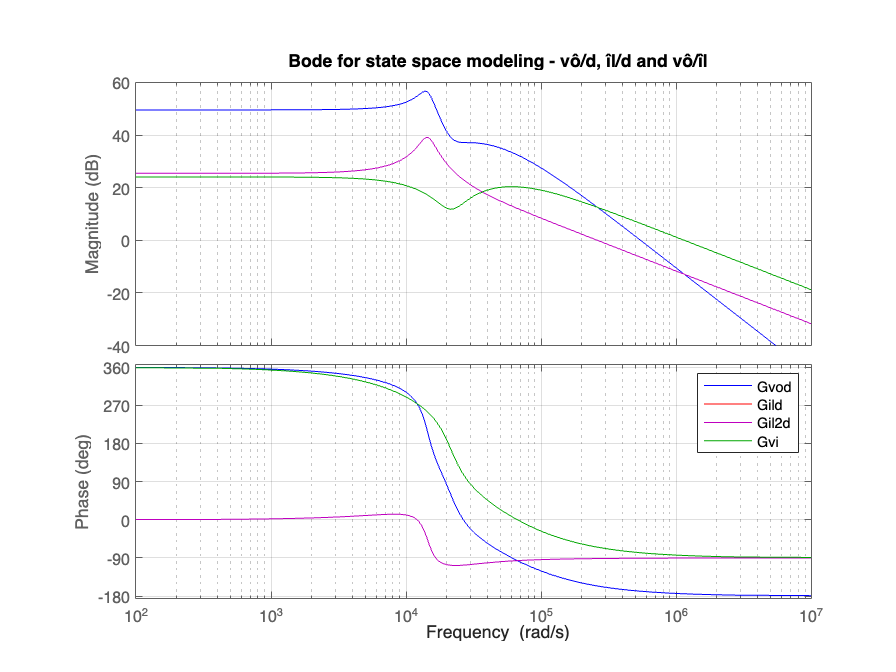


% Definindo os valores reais
valores = [C1, C2, L1, L2, Ro, Vi, d]; %simbolic
numeros = [C1_val, C2_val, L1_val, L2_val,  Rload, Vin,  D]; % Exemplo de valores

% Substituição (exceto o 's')
Gvo_num_sym = subs(G_vo_d, valores, numeros);
G_iL_d_num_sym = subs(G_iL_d, valores, numeros);
G_iL2_d_num_sym = subs(G_iL2_d, valores, numeros);
G_vi_real = Gvo_num_sym / G_iL2_d_num_sym;
G_vi_num_sym = subs(G_iL_d, valores, numeros);

% Separa numerador e denominador do resultado simbólico
[Num, Den] = numden(Gvo_num_sym);
[Num1, Den1] = numden(G_iL_d_num_sym);
[Num2, Den2] = numden(G_iL2_d_num_sym);
[Num3, Den3] = numden(G_vi_num_sym);
[Num4, Den4] = numden(G_vi_real);

% Converte os polinômios simbólicos em vetores numéricos de coeficientes
% O MATLAB extrai na ordem: [s^n, s^(n-1), ..., s^0]
num_vetor = double(sym2poly(Num));
den_vetor = double(sym2poly(Den));
num_vetor1 = double(sym2poly(Num1));
den_vetor1 = double(sym2poly(Den1));
num_vetor2 = double(sym2poly(Num2));
den_vetor2 = double(sym2poly(Den2));
num_vetor3 = double(sym2poly(Num3));
den_vetor3 = double(sym2poly(Den3));
num_vetor4 = double(sym2poly(Num4));
den_vetor4 = double(sym2poly(Den4));
% Se o ganho ficar muito alto no numerador, pode ser necessário normalizar
% dividindo ambos pelo primeiro termo do denominador:
num_vetor = num_vetor / den_vetor(1);
den_vetor = den_vetor / den_vetor(1);

num_vetor1 = num_vetor1 / den_vetor1(1);
den_vetor1 = den_vetor1 / den_vetor1(1);

num_vetor2 = num_vetor2 / den_vetor2(1);
den_vetor2 = den_vetor2 / den_vetor2(1);

num_vetor3 = num_vetor3 / den_vetor3(1);
den_vetor3 = den_vetor3 / den_vetor3(1);

% Cria a Função de Transferência Numérica
sys = tf(num_vetor, den_vetor);
sys_iL = tf(num_vetor1, den_vetor1);
sys_iL2 = tf(num_vetor2, den_vetor2);
sys_vi = tf(num_vetor3, den_vetor3);
sys_vi_r = tf(num_vetor4, den_vetor4);

figure;
bode(sys, 'b-', sys_iL, 'r-', sys_iL2, 'm-', sys_vi_r, 'g-');%, G3, 'g-', G4, 'm-');
grid on;
legend('Gvod', 'Gild','Gil2d',  'Gvi', ...
       'Location', 'northeast');
%title('GVod GiL1d');
title('Bode for state space modeling - vô/d, îl/d and vô/îl');
grid on;

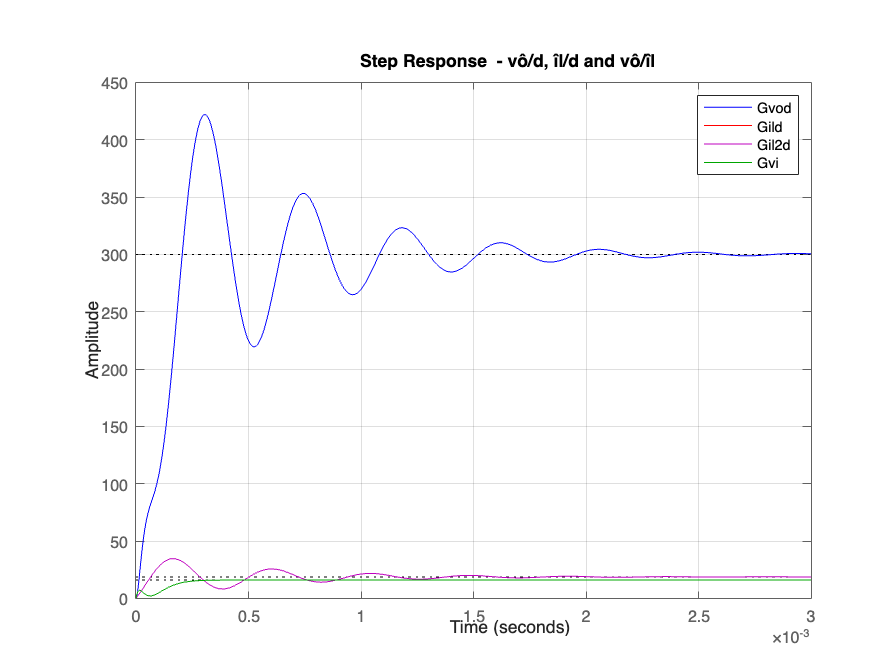


% % Save as EPS
% fig_folder = 'figures';
% 
% filename_eps = fullfile(fig_folder, 'cuk_all_bode.png');
%%  % print(gcf, filename_eps, '-depsc', '-r300');
% fprintf('Saved: %s\n', filename_eps);


figure;
step(sys, 'b-', sys_iL, 'r-', sys_iL2, 'm-', sys_vi_r, 'g-') %, G3, 'g-', G4, 'm-');
grid on;
legend('Gvod', 'Gild','Gil2d', 'Gvi', ...
       'Location', 'northeast');

title('Step Response  - vô/d, îl/d and vô/îl ');

 %%  % print(gcf, 'figures/cuk_allstep_response.png',  '-depsc', '-r300');

FT_G_Vod=sys;
% Exibir a função de transferência
disp('G(s) = vo/d ');

G(s) = vo/d 


disp(FT_G_Vod);

  tf with properties:

       Numerator: {[0 0 3.0000e+11 -3.0000e+15 1.3889e+20]}
     Denominator: {[1 100000 2.7852e+09 2.8519e+13 4.6296e+17]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]





FT_G_iLd=sys_iL;
% Exibir a função de transferência
disp('G(s) = iL1/d');

G(s) = iL1/d


disp(FT_G_iLd);

  tf with properties:

       Numerator: {[0 2.6042e+05 2.7778e+10 8.6806e+14 8.6806e+18]}
     Denominator: {[1 100000 2.7852e+09 2.8519e+13 4.6296e+17]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




FT_G_iL2d=sys_iL2;
% Exibir a função de transferência
disp('G(s) = iL2/d');

G(s) = iL2/d


disp(FT_G_iL2d);

  tf with properties:

       Numerator: {[0 2.6042e+05 2.7778e+10 8.6806e+14 8.6806e+18]}
     Denominator: {[1 100000 2.7852e+09 2.8519e+13 4.6296e+17]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Exibir a função de transferência
disp(' G(s) = Vo/iL');

 G(s) = Vo/iL


FT_G_Vi = FT_G_Vod / FT_G_iLd

FT_G_Vi =
 
             3e11 s^6 + 2.7e16 s^5 + 6.744e20 s^4 + 1.409e25 s^3 + 4.402e29 s^2 + 2.572e33 s + 6.43e37
  ---------------------------------------------------------------------------------------------------------------
  2.604e05 s^7 + 5.382e10 s^6 + 4.371e15 s^5 + 1.803e20 s^4 + 4.198e24 s^3 + 6.179e28 s^2 + 6.494e32 s + 4.019e36
 
Continuous-time transfer function.


disp(FT_G_Vi);

  tf with properties:

       Numerator: {[0 3.0000e+11 2.7000e+16 6.7444e+20 1.4089e+25 4.4016e+29 2.5720e+33 6.4300e+37]}
     Denominator: {[2.6042e+05 5.3819e+10 4.3711e+15 1.8028e+20 4.1985e+24 6.1793e+28 6.4943e+32 4.0188e+36]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



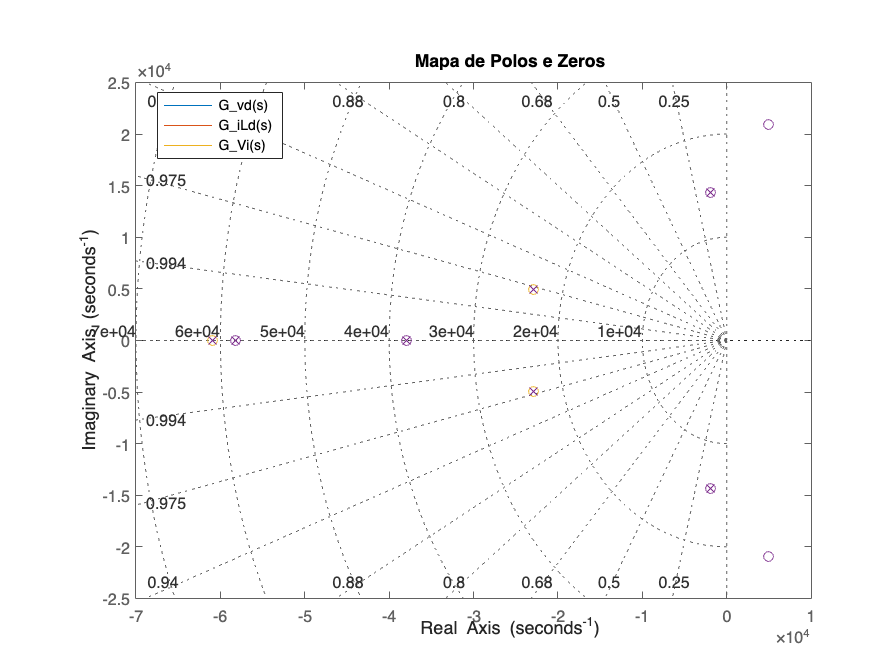



%  Mapa de polos e zeros
pzmap(FT_G_Vod);
hold on;
pzmap(FT_G_iLd);
grid on;
pzmap(FT_G_iL2d);
hold on;
pzmap(FT_G_Vi);
grid on;
title('Mapa de Polos e Zeros');
legend('G_{vd}(s)', 'G_{iLd}(s)','G_{Vi}(s)', 'Location', 'best');

#### COMPARATIVO MODELAGEM

Vg = Vi;                           % Voltage de entrada
Vo = (D/(1-D)) * Vi;              % Voltage de saída
Vc1 = Vg / (1-D);                 % Voltage no capacitor C1
Io = Vo / Ro;                      % Corrente de saída
IL2 = Io;                         % Corrente no indutor L2
IL1 = (D/(1-D)) * Io;             % Corrente no indutor L1
P = Vo^2 / Ro;                     % Potência de saída


Vg = Vin;                           % Voltage de entrada
Vo = (D/(1-D)) * Vin;              % Voltage de saída
Vc1 = Vg / (1-D);                 % Voltage no capacitor C1
Io_val = Vo / Rload;                      % Corrente de saída
IL2 = Io_val;                         % Corrente no indutor L2
IL1 = (D_val/(1-D_val)) * Io_val;             % Corrente no indutor L1
P = Vo^2 / Rload;                     % Potência de saída



%% Matrizes do modelo médio de grandes sinais
% A1 = modo 1 (interruptor ligado, diodo desligado)
A1 = [0,       0,       0,       0;
      0,       0,      -1/C1_val,    0;
      0,       1/L2_val,    0,      -1/L2_val;
      0,       0,       1/C2_val,   -1/(Rload*C2_val)];

% A2 = modo 2 (interruptor desligado, diodo ligado)
A2 = [0,      -1/L1_val,    0,       0;
      1/C1_val,    0,       0,       0;
      0,       0,       0,      -1/L2_val;
      0,       0,       1/C2_val,   -1/(Rload*C2_val)];

% Matriz A no ponto de equilíbrio (d = D)
A = D_val*A1 + (1-D_val)*A2;
B = [1/L1_val; 0; 0; 0];

fprintf('MATRIZ A (sistema linearizado no ponto de equilíbrio)\n');

MATRIZ A (sistema linearizado no ponto de equilíbrio)


disp(A);

   1.0e+06 *

         0   -0.0009         0         0
    0.2133         0   -0.3200         0
         0    0.0003         0   -0.0005
         0         0    4.8000   -0.1000




%% Vetor F = (A1 - A2)*X (linearização em relação a d)
% Vetor de estado de equilíbrio X 
X = [IL1; Vc1; IL2; Vo];

% Diferença das matrizes de modo
A1_minus_A2 = A1 - A2;

% Vetor F (entrada de controle d)
F = A1_minus_A2 * X;
%% MATRIZES DE SAÍDA

% Matriz de saída para tensão de saída (vo = x4)
C_vout = [0, 0, 0, 1];

% Matriz de saída para corrente no indutor L1 (iL1 = x1)
C_iL1 = [1, 0, 0, 0];

% Matriz de saída para corrente no indutor L2 (iL2 = x1)
C_iL2 = [0, 0, 1, 0];

% Matriz de alimentação direta (nenhuma)
Dmat = 0;

%  Voltage de saída / razão cíclica: Gvd(s) = vo(s)/d(s)
sys_vout = ss(A, F, C_vout, Dmat);
Gvd = tf(sys_vout);

% Corrente no indutor L1 / razão cíclica: GiL1d(s) = iL1(s)/d(s)
sys_iL1 = ss(A, F, C_iL1, Dmat);
GiL1d = tf(sys_iL1);

% Corrente no indutor L2/ razão cíclica: GiL1d(s) = iL2(s)/d(s)
sys_iL2 = ss(A, F, C_iL2, Dmat);
GiL2d = tf(sys_iL2);

fprintf('FUNÇÕES DE TRANSFERÊNCIA OBTIDAS\n');

FUNÇÕES DE TRANSFERÊNCIA OBTIDAS


fprintf(' Gvd(s) = vo(s)/d(s):\n');

 Gvd(s) = vo(s)/d(s):


Gvd

Gvd =
 
              3e11 s^2 - 3e15 s + 1.389e20
  ----------------------------------------------------
  s^4 + 1e05 s^3 + 2.785e09 s^2 + 2.852e13 s + 4.63e17
 
Continuous-time transfer function.
Model Properties



fprintf(' GiL1d(s) = iL1(s)/d(s):\n');

 GiL1d(s) = iL1(s)/d(s):


GiL1d

GiL1d =
 
  2.604e05 s^3 + 2.778e10 s^2 + 8.681e14 s + 8.681e18
  ----------------------------------------------------
  s^4 + 1e05 s^3 + 2.785e09 s^2 + 2.852e13 s + 4.63e17
 
Continuous-time transfer function.
Model Properties



fprintf(' GiL2d(s) = iL2(s)/d(s):\n');

 GiL2d(s) = iL2(s)/d(s):


GiL2d

GiL2d =
 
   6.25e04 s^3 + 5.625e09 s^2 - 3.356e13 s + 2.894e18
  ----------------------------------------------------
  s^4 + 1e05 s^3 + 2.785e09 s^2 + 2.852e13 s + 4.63e17
 
Continuous-time transfer function.
Model Properties



Gvi = Gvd / GiL2d;
fprintf('\n Gvi(s) = vô(s)/iL2(s) :\n');


 Gvi(s) = vô(s)/iL2(s) :


Gvi

Gvi =
 
           3e11 s^6 + 2.7e16 s^5 + 6.744e20 s^4 + 1.409e25 s^3 + 4.402e29 s^2 + 2.572e33 s + 6.43e37
  ------------------------------------------------------------------------------------------------------------
  6.25e04 s^7 + 1.188e10 s^6 + 7.03e14 s^5 + 1.699e19 s^4 + 3.852e23 s^3 + 9.706e27 s^2 + 6.698e31 s + 1.34e36
 
Continuous-time transfer function.



 %  coeficientes
[num_vec0, den_vec0] = tfdata(GiL2d, 'v');
num_vec0= num_vec0(find(num_vec0 ~= 0, 1):end);
den_vec0 = den_vec0(find(den_vec0 ~= 0, 1):end);

% Extrair coeficientes
[num_vec1, den_vec1] = tfdata(Gvd, 'v');
% Remover zeros 
num_vec1 = num_vec1(find(num_vec1 ~= 0, 1):end);
den_vec1 = den_vec1(find(den_vec1 ~= 0, 1):end);

 %  coeficientes
[num_vec2, den_vec2] = tfdata(GiL1d, 'v');
num_vec2= num_vec2(find(num_vec2 ~= 0, 1):end);
den_vec2 = den_vec2(find(den_vec2 ~= 0, 1):end);

 %  coeficientes
[num_vec3, den_vec3] = tfdata(Gvi, 'v');
num_vec3= num_vec3(find(num_vec3 ~= 0, 1):end);
den_vec3 = den_vec3(find(den_vec3 ~= 0, 1):end);


% Polos (mesmos para ambas as FT - característicos do sistema)
polos = pole(Gvd);
polos_gid =  pole(GiL1d);
polos_gi2d =  pole(GiL2d);
polos_gvi =  pole(Gvi);
% Zeros
zeros_vout = zero(Gvd);
zeros_iL1 = zero(GiL1d);
zeros_iL2 = zero(GiL2d);
zeros_Gvi = zero(Gvi);

% fprintf('POLOS E ZEROS\n');
% fprintf('   Polos do sistema Gvi :\n');
% for i = 1:length(polos_gvi)
%     fprintf('      s%d = %.4f %+.4fi\n', i, real(polos_gvi(i)), imag(polos_gvi(i)));
% end
% for i = 1:length(polos_gid)
%     fprintf('      s%d = %.4f %+.4fi\n', i, real(polos_gid(i)), imag(polos_gid(i)));
% end
% 
% fprintf('   Polos do sistema Gvod (4ª ordem):\n');
% for i = 1:length(polos)
%     fprintf('      s%d = %.4f %+.4fi\n', i, real(polos(i)), imag(polos(i)));
% end
% 
% 
% fprintf('\n   Zeros de Gvd(s):\n');
% for i = 1:length(zeros_vout)
%     fprintf('      z%d = %.4f %+.4fi\n', i, real(zeros_vout(i)), imag(zeros_vout(i)));
% end
% fprintf('\n   Zeros de GiL1d(s):\n');
% for i = 1:length(zeros_iL1)
%     fprintf('      z%d = %.4f %+.4fi\n', i, real(zeros_iL1(i)), imag(zeros_iL1(i)));
% end

% Ganhos DC
dc_gain_vout = dcgain(Gvd);
dc_gain_iL1 = dcgain(GiL1d);
dc_gain_iL2 = dcgain(GiL2d);
dc_gain_gvi = dcgain(Gvi);

fprintf('      Gvd(0) = %.4f ( -vo = %.4f)\n', dc_gain_vout, -Vo);

      Gvd(0) = 300.0000 ( -vo = -72.0000)


fprintf('      GiL1d(0) = %.4f ( iL1/d = %.4f)\n', dc_gain_iL1, IL1/D);

      GiL1d(0) = 18.7500 ( iL1/d = 3.7500)


fprintf('      GiL2d(0) = %.4f ( iL2/d = %.4f)\n', dc_gain_iL2, IL2/D);

      GiL2d(0) = 6.2500 ( iL2/d = 2.5000)


fprintf('      Gvi(0) = %.4f ( vo/il1 = %.4f)\n', dc_gain_gvi, Vo/IL2);

      Gvi(0) = 48.0000 ( vo/il1 = 48.0000)



figure;
bode(Gvd, 'b-', GiL1d, 'r-', GiL2d, 'g-', Gvi, 'm-') %, G3, 'g-', G4, 'm-');
hold on;
grid on;
margin;

 Here is an example of how the function margin works:
 Consider a randomly generated stable Transfer Function Model:
 of the form G(s)=num(s)/den(s):


num =          0         0    0.4434    0.1158


den =     1.0000    6.4907  200.1113  957.0286


Call margin using the following command (see also, help margin):
margin(tf(num,den));


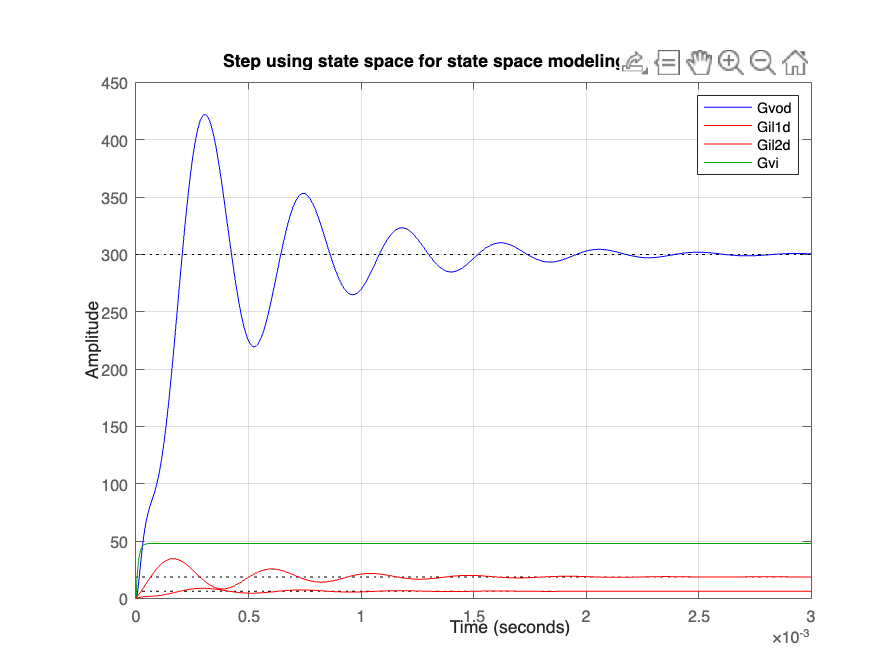

legend('Gvod', 'Gil1d', 'Gil2d', 'Gvi', ...
       'Location', 'northeast');
%title('GVod GiL1d');
title('Bode for state space modeling - vô/d e îl2/d e vô/îl2');
grid on;
%%  % print(gcf, 'figures/bodecuk_all_ss_bode.png',  '-depsc', '-r300');


figure;
step(Gvd, 'b-', GiL1d, 'r-', GiL2d, 'r-');% , Gvi, 'g-') %, G3, 'g-', G4, 'm-');
grid on;
legend('Gvod', 'Gil1d', 'Gil2d', 'Gvi', ...
       'Location', 'northeast');
%title('GVod GiL1d');
title('Step using state space for state space modeling - vô/d e îl2/d e vô/îl2');
grid on;

%%  % print(gcf, 'figures/stepcuk_all_ss_bode.png',  '-depsc', '-r300');


%% (MÉTODO DE THÉVENIN) - substituicao de fonte

Dp = 1 - D;
den_val = s^4*Rload*L1_val*L2_val*C1_val*C2_val + s^3*L1_val*L2_val*C1_val + ...
          s^2*Rload*(L1_val*C1_val + D^2*L2_val*C2_val + L1_val*C2_val*Dp^2 + L1_val*C2_val*D) + ...
          s*(L1_val*D^2 + L2_val*Dp^2) + Rload*Dp^2;

num_vd_val = -(Rload*D*Vin)/Dp + s*(Rload*L1_val/Vin)*P + Rload*Vin;

num_id_val = (Vin/Dp) * (s^3*Rload*L1_val*C1_val*C2_val + s^2*L1_val*(C1_val - (C2_val*D^2)/Dp) + ...
             s*(Rload*C2_val*Dp - (L1_val*D^2)/(Rload*Dp)) + Dp)

$$num\_id\_val = \frac{1411219032094515549194917919195841\,s^{3}}{1361129467683753853853498429727072845824000000}+\frac{53790705718937037\,s^{2}}{576460752303423488000000}-\frac{41084588400965895\,s}{73786976294838206464}+48$$

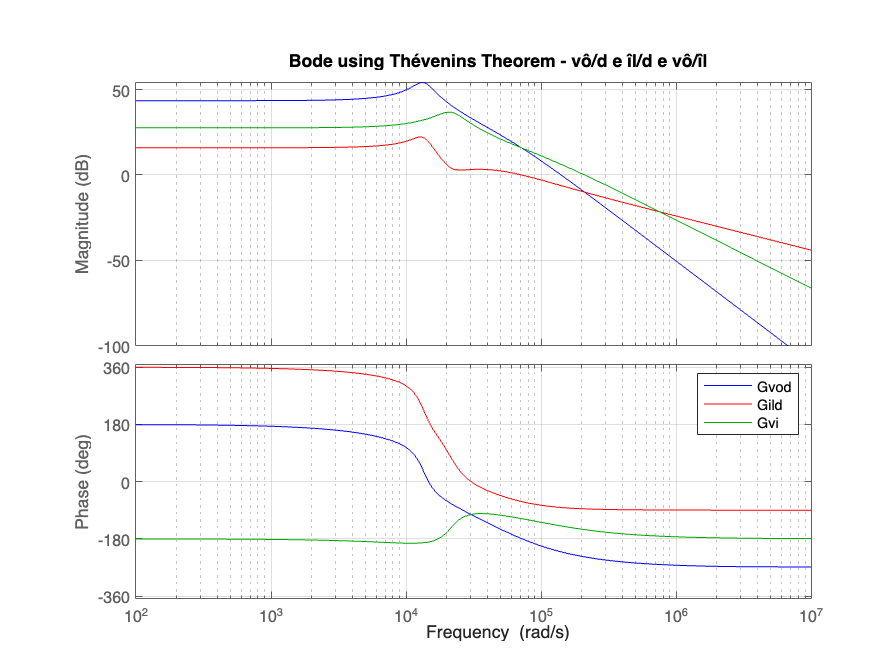


% Transfer Functions
% Convert symbolic to numeric polynomial coefficients
den_coeffs = double(sym2poly(den_val));
num_vd_coeffs = double(sym2poly(num_vd_val));
num_id_coeffs = double(sym2poly(num_id_val));

% Create transfer functions
Gvd_thevenin_own = tf(num_vd_coeffs, den_coeffs);
Gid_thevenin_own = tf(num_id_coeffs, den_coeffs);
Gvi_full_thevenin_own  = minreal(Gvd_thevenin_own / Gid_thevenin_own); % Planta Completa


figure;
bode(Gvd_thevenin_own, 'b-', Gid_thevenin_own, 'r-', Gvi_full_thevenin_own, 'g-') %, G3, 'g-', G4, 'm-');
grid on;
legend('Gvod', 'Gild', 'Gvi', ...
       'Location', 'northeast');
%title('GVod GiL1d');
title('Bode using Thévenins Theorem - vô/d e îl/d e vô/îl');
grid on;





% Extrair coeficientes
[num_vec_th_1, den_vec_th_1] = tfdata(Gvd_thevenin_own, 'v');
% Remover zeros 
num_vec_th_1 = num_vec_th_1(find(num_vec_th_1 ~= 0, 1):end);
den_vec_th_1 = den_vec_th_1(find(den_vec_th_1 ~= 0, 1):end);
%  coeficientes
[num_vec_th_2, den_vec_th_2] = tfdata(Gid_thevenin_own, 'v');
num_vec_th_2= num_vec_th_2(find(num_vec_th_2 ~= 0, 1):end);
den_vec_th_2 = den_vec_th_2(find(den_vec_th_2 ~= 0, 1):end);
%  coeficientes
[num_vec_th_3, den_vec_th_3] = tfdata(Gvi_full_thevenin_own, 'v');
num_vec_th_3= num_vec_th_3(find(num_vec_th_3 ~= 0, 1):end);
den_vec_th_3 = den_vec_th_3(find(den_vec_th_3 ~= 0, 1):end);


%-------------------------------------------------------------------------------------------------------------------------
%% (MÉTODO DE THÉVENIN) - VALIDAÇÃO article
% Num Gv(s)
d4 = Ro*L1*L2*C1*C2;
d3 = L1*L2*C1;
d2 = Ro * (L1*C2*D^2 + L2*C2*d^2 + L1*C1);
d1 = (L1*D^2 + L2*d^2);
d0 = Ro * d^2;
den = d4*s^4 + d3*s^3 + d2*s^2 + d1*s + d0;
n_vd2 = (Ro*L1*C1*Vi) / d;
n_vd1 = (Ro*L1*(Vi/Ro)) / d; % Assumindo P/E ou corrente de regime
n_vd0 = Ro*Vi;
Gvd_Thev = -(n_vd2*s^2 - n_vd1*s + n_vd0) / den;
% Display
disp('Gvd_Thev(s) =  ');

Gvd_Thev(s) =  


pretty(Gvd_Thev);

                                                 2
                                    C1 L1 Ro Vi s    L1 Vi s
                                    -------------- - ------- + Ro Vi
                                           d            d
- ---------------------------------------------------------------------------------------------------
    /     2   9 L1 \       2       2 /        2           9 C2 L1 \             3                   4
  s | L2 d  + ---- | + Ro d  + Ro s  | C2 L2 d  + C1 L1 + ------- | + C1 L1 L2 s  + C1 C2 L1 L2 Ro s
    \          25  /                 \                       25   /




% -------------------------
% Gid(s) = I_L2(s) / D(s)= V_o(s) / I_L2(s)
gain_id = Vi / d;
n_id3 = Ro*L1*C1*C2;
n_id2 = L1 * (C1 - (C2*D^2)/d);
n_id1 = Ro*C2*d - (L1*D^2)/(Ro*d);
n_id0 = d;

Gid_thev = gain_id * (n_id3*s^3 + n_id2*s^2 + n_id1*s + n_id0) / den;
% Display
disp('Gid_th(s) = I_L2(s)/D(s) = ');

Gid_th(s) = I_L2(s)/D(s) = 


pretty(Gid_thev);

                   /              3      /      9 C2 \  2   /             9 L1  \       \
                Vi | C1 C2 L1 Ro s  + L1 | C1 - ---- | s  + | C2 Ro d - ------- | s + d |
                   \                     \      25 d /      \           25 Ro d /       /
---------------------------------------------------------------------------------------------------------
  /   /     2   9 L1 \       2       2 /        2           9 C2 L1 \             3                   4 \
d | s | L2 d  + ---- | + Ro d  + Ro s  | C2 L2 d  + C1 L1 + ------- | + C1 L1 L2 s  + C1 C2 L1 L2 Ro s  |
  \   \          25  /                 \                       25   /                                   /



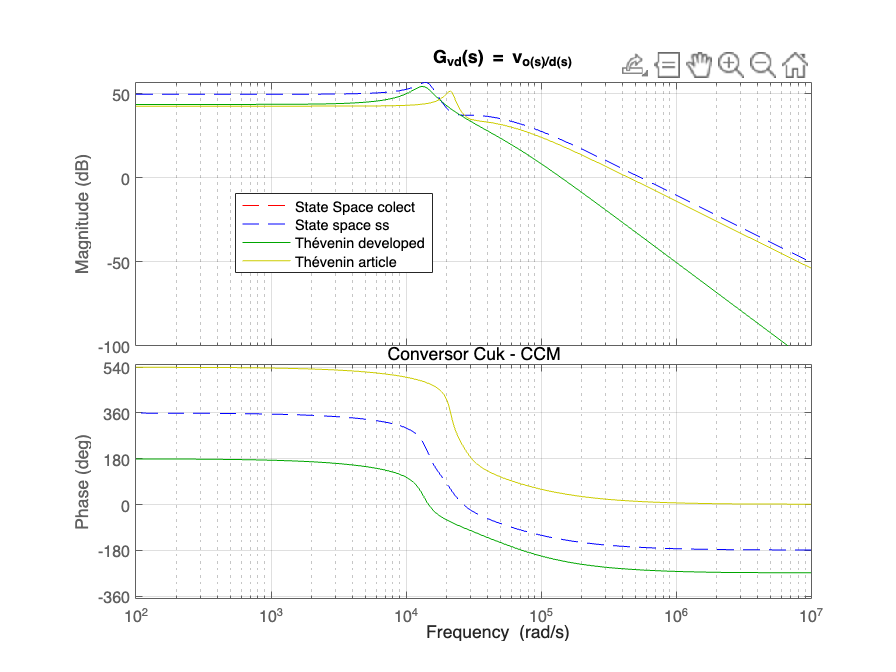



% -------------------------

Gvi_simplified = Gvd_Thev/Gid_thev;
Gvo_thevenin = subs(Gvd_Thev, valores, numeros);
G_iL_d_thevenin = subs(Gid_thev, valores, numeros);
G_vi_num_sym_thevenin = subs(Gvi_simplified, valores, numeros);

% ----------------------------
% THÉVENIN WITH VALUES
d4 = Rload * L1_val * L2_val * C1_val * C2_val;
d3 = L1_val * L2_val * C1_val;
d2 = Rload * (L1_val * C2_val * D^2 + L2_val * C2_val * D^2 + L1_val * C1_val);
d1 = (L1_val * D^2 + L2_val * D^2);
d0 = Rload * D^2;
den = [d4 d3 d2 d1 d0];
% FT Gvd (Voltage de saída / Duty cycle) - Screenshot 4.05.23
% Note o sinal negativo pois o Cuk é um conversor inversor
n_vd2 = (Rload * L1_val * C1_val * Vin) / D;
n_vd1 = (Rload * L1_val * (Vin/Rload)) / D; % P/E simplificado para regime permanente
n_vd0 = Rload * Vin;
num_vd = -[n_vd2 -n_vd1 n_vd0]; % O sinal negativo é vital
Gvd_thevenin_tf = tf(num_vd, den);

% F)T Gid (Corrente no Indutor L2 / Duty cycle) 
gain_id = Vin / D;
n_id3 = Rload * L1_val * C1_val * C2_val;
n_id2 = L1_val * (C1_val - (C2_val * D^2) / D);
n_id1 = Rload * C2_val * D - (L1_val * D^2) / (Rload * D);
n_id0 = D;

num_id = gain_id * [n_id3 n_id2 n_id1 n_id0];

%Gid_th = gain_id * (n_id3*s^3 + n_id2*s^2 + n_id1*s + n_id0) / den
Gid_thevenin_tf = tf(num_id, den);

%  FT Gvi (Relação Voltage/Corrente L2) 
Gvi_th = Gvd_thevenin_tf / Gid_thevenin_tf;




% Extrair coeficientes
[num_vec_th_article_1, den_vec_th_article_1] = tfdata(Gvd_thevenin_tf, 'v');
% Remover zeros 
num_vec_th_article_1 = num_vec_th_article_1(find(num_vec_th_article_1 ~= 0, 1):end);
den_vec_th_article_1 = den_vec_th_article_1(find(den_vec_th_article_1 ~= 0, 1):end);
%  coeficientes
[num_vec_th_article_2, den_vec_th_article_2] = tfdata(Gid_thevenin_tf, 'v');
num_vec_th_article_2= num_vec_th_article_2(find(num_vec_th_article_2 ~= 0, 1):end);
den_vec_th_article_2 = den_vec_th_article_2(find(den_vec_th_article_2 ~= 0, 1):end);
%  coeficientes
[num_vec_th_article_3, den_vec_th_article_3] = tfdata(Gvi_th, 'v');
num_vec_th_article_3= num_vec_th_article_3(find(num_vec_th_article_3 ~= 0, 1):end);
den_vec_th_article_3 = den_vec_th_article_3(find(den_vec_th_article_3 ~= 0, 1):end);




%  Bode da tensão de saída
figure;
bode(FT_G_Vod,'r--', Gvd, 'b--', Gvd_thevenin_own, 'g', Gvd_thevenin_tf, 'y');
% bode(Gvd, Gvd_thevenin_own, 'r--', {100, 10000});
% bode(Gvd, Gvd_thevenin_tf, 'r--', {100, 10000});
grid on;
legend('State Space colect', 'State space ss' ,'Thévenin developed', 'Thévenin article', 'Location', 'southwest');
title(' G_{vd}(s) = v_o(s)/d(s)');
subtitle('Conversor Cuk - CCM');

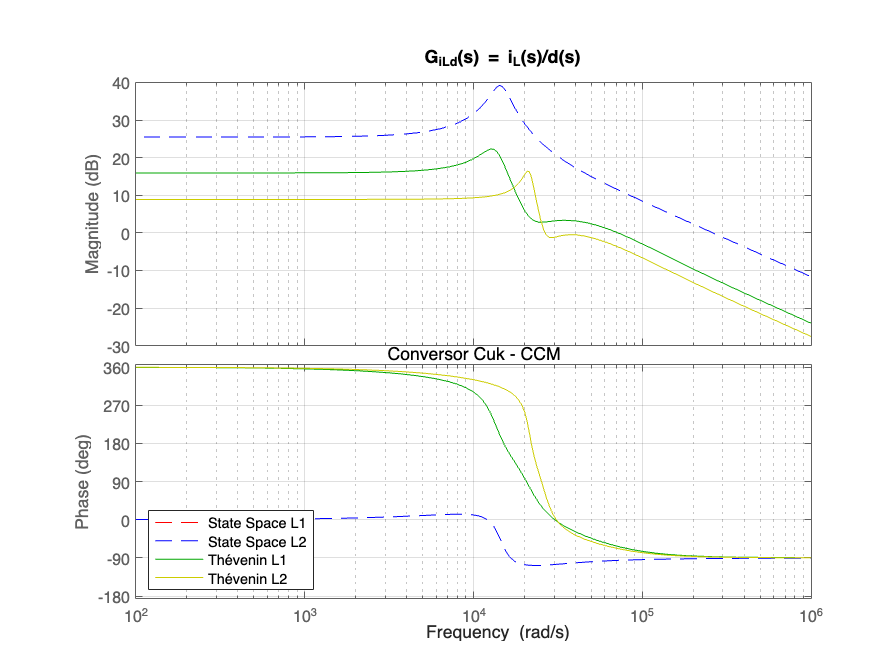


% Bode da corrente no indutor L2
figure;
FT_G_Vi = FT_G_Vod / FT_G_iL2d;

bode(FT_G_iLd, 'r--',FT_G_iL2d, 'b--', Gid_thevenin_own,'g',  Gid_thevenin_tf, 'y');
%bode(FT_G_iLd, Gid_thevenin_own, 'r--', {100, 10000});
%bode(GiL1d, Gid_thevenin_tf, 'r--', {100, 10000});
% bode(GiL1d, Gid_thevenin_own, 'r--', {100, 10000});
grid on;
legend('State Space L1', 'State Space L2', 'Thévenin L1', 'Thévenin L2', 'Location', 'southwest');
title(' G_{iLd}(s) = i_{L}(s)/d(s)');
subtitle('Conversor Cuk - CCM');

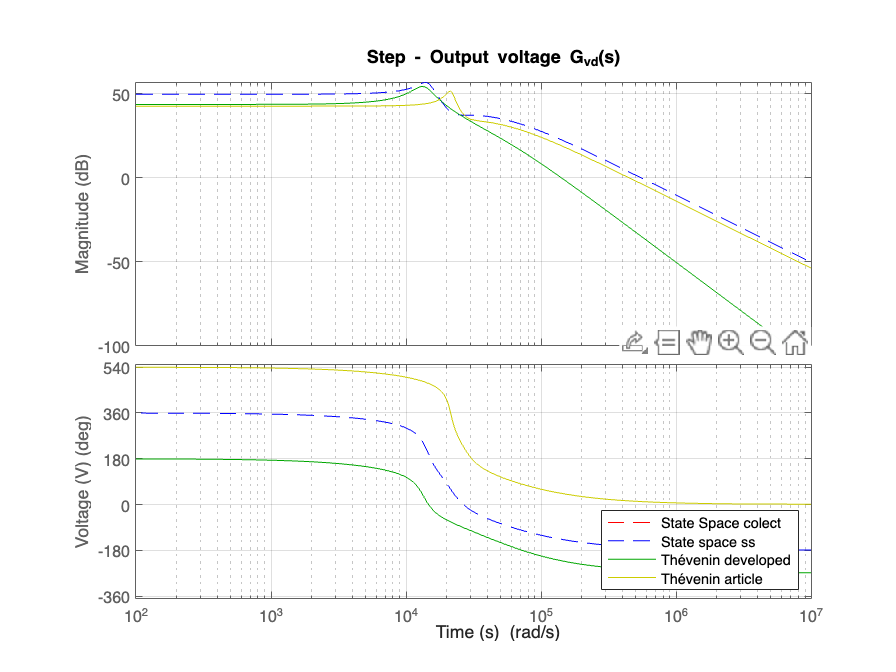

% % print(gcf, 'figures/bode_cuk_allbode.png',  '-depsc', '-r300');

% Resposta ao degrau da tensão de saída
figure;
bode(FT_G_Vod,'r--', Gvd, 'b--', Gvd_thevenin_own, 'g', Gvd_thevenin_tf, 'y');
grid on;
legend('State Space colect', 'State space ss' ,'Thévenin developed', 'Thévenin article', 'Location', 'southeast');
title('Step - Output voltage G_{vd}(s) ');
xlabel('Time (s)');
ylabel('Voltage (V)');

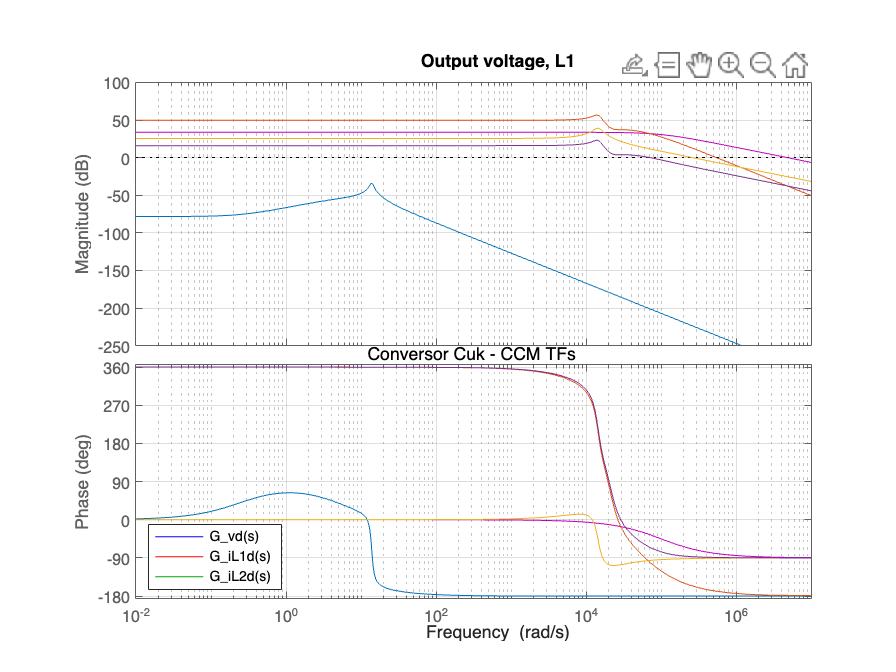

%%  % print(gcf, 'figures/stepcuk_all_ss_bode.png',  '-depsc', '-r300');

% 
% % Resposta ao degrau da corrente no indutor 
% figure(4);
% step(FT_G_iLd, 'r--', GiL1d, 'b--', Gid_thevenin_own,  'g', Gid_thevenin_tf, 'y');
% grid on;
% legend('State Space colect', 'State space ss' ,'Thévenin developed', 'Thévenin article', 'Location', 'southwest');
% title('Step Response - Corrente no Indutor L1');
% xlabel('Time (s)');
% ylabel('Corrente (A)');

% Bode comparativo
figure(5);
bode(Gvd, GiL1d, GiL2d);
grid on;
legend('G_{vd}(s)', 'G_{iL1d}(s)', 'G_{iL2d}(s)','Location', 'southwest');
title('Conversor Cuk - CCM TFs ');

% print(gcf, 'figures/stepcuk_all_ss_bode.png',  '-depsc', '-r300');


%%ANÁLISE DE CONTROLABILIDADE E OBSERVABILIDADE
fprintf('\nANÁLISE DE CONTROLABILIDADE E OBSERVABILIDADE\n');


ANÁLISE DE CONTROLABILIDADE E OBSERVABILIDADE



% Matriz de controlabilidade
Co = ctrb(A, F);
rank_Co = rank(Co);
fprintf('   Controlabilidade: rank = %d / %d -> ', rank_Co, length(A));

   Controlabilidade: rank = 3 / 4 -> 

if rank_Co == length(A)
    fprintf('Sistema CONTROLÁVEL\n');
else
    fprintf('Sistema NÃO CONTROLÁVEL\n');
end

Sistema NÃO CONTROLÁVEL



% Observabilidade para tensão de saída
Ob_vout = obsv(A, C_vout);
rank_Ob_vout = rank(Ob_vout);
fprintf('   Observabilidade (vo): rank = %d / %d -> ', rank_Ob_vout, length(A));

   Observabilidade (vo): rank = 3 / 4 -> 

if rank_Ob_vout == length(A)
    fprintf('Sistema OBSERVÁVEL (saída vo)\n');
else
    fprintf('Sistema NÃO OBSERVÁVEL (saída vo)\n');
end

Sistema NÃO OBSERVÁVEL (saída vo)



% Observabilidade para corrente L1
Ob_iL1 = obsv(A, C_iL1);
rank_Ob_iL1 = rank(Ob_iL1);
fprintf('   Observabilidade (iL1): rank = %d / %d -> ', rank_Ob_iL1, length(A));

   Observabilidade (iL1): rank = 4 / 4 -> 

if rank_Ob_iL1 == length(A)
    fprintf('Sistema OBSERVÁVEL (saída iL1)\n');
else
    fprintf('Sistema NÃO OBSERVÁVEL (saída iL1)\n');
end

Sistema OBSERVÁVEL (saída iL1)




fprintf('\n MODELOS SALVOS EM "modelo_cuk_completo.mat"\n');


8. MODELOS SALVOS EM "modelo_cuk_completo.mat"



fprintf('Função Thévenin Gvd(s) = vo(s)/d(s):\n');

Função Thévenin Gvd(s) = vo(s)/d(s):





fprintf('   Zero RHP: %s\n', string(any(real(zeros_iL1) > 0)));

   Zero RHP: false


fprintf('\nOBSERVAÇÃO IMPORTANTE:\n');


OBSERVAÇÃO IMPORTANTE:


fprintf('   - Gvd(s) possui um zero no semiplano direito (RHP),\n');

   - Gvd(s) possui um zero no semiplano direito (RHP),


fprintf('     característica de sistemas de fase não-mínima.\n');

     característica de sistemas de fase não-mínima.


fprintf('   - GiL1d(s) possui zero no semiplano esquerdo (LHP),\n');

   - GiL1d(s) possui zero no semiplano esquerdo (LHP),


fprintf('     sendo mais adequada para malhas internas de corrente.\n');

     sendo mais adequada para malhas internas de corrente.


fprintf('========================================\n');

#### PROJETO DO CONTROLADOR PI PARA A MALHA DE CORRENTE 

fs=50e3; 
fci=2e3; 
fcv=200; 
margem_de_fase_current = 60;


D=0.6; Dp=1-D;
Vo=72; 
Io_nom=Vo/Po; 


% Current sensor gain
Ki = V_sensor_max / Io_nom;  % V/A
fprintf('Current sensor gain: Ki = %.4f V/A\n', Ki);

Current sensor gain: Ki = 13.7500 V/A


fprintf('  (Outputs %.1f V when iL = %.3f A)\n', V_sensor_max, Io_nom);

  (Outputs 3.3 V when iL = 0.240 A)



Kv = V_sensor_max / Vo;  % V/V (dimensionless)
fprintf('Voltage sensor gain: Kv = %.6f V/V\n', Kv);

Voltage sensor gain: Kv = 0.045833 V/V


fprintf('  (Outputs %.1f V when vo = %.1f V)\n', V_sensor_max, Vo);

  (Outputs 3.3 V when vo = 72.0 V)



% Ganhos dos sensores e PWM

Kpwm=1; KPWM=Kpwm;
%KPWM = 1/5;           % Ganho do modulador PWM(pico de 5V)


omega_r = 2 * pi * fr;          % Frequência angular da rede [rad/s]
omega_s = 2 * pi * fs;           % Frequência angular de comutação [rad/s]
I_rms = Po / Vrms;               % Corrente eficaz nominal [A]

% Frequência de ressonância entre 10*fr e fs/10
fres = 100 * fr;
omega_res = 2*pi*fres;

fprintf('Frequência angular da rede: %.2f rad/s\n', omega_r);

Frequência angular da rede: 376.99 rad/s


fprintf('Frequência angular de comutação: %.2f rad/s\n', omega_s);

Frequência angular de comutação: 314159.27 rad/s


fprintf('Corrente eficaz nominal: %.2f A\n', I_rms);

Corrente eficaz nominal: 43.30 A





fprintf(' PROJETO DO CONTROLADOR PI - MALHA DE CORRENTE (iL1) e (iL2)\n');

 PROJETO DO CONTROLADOR PI - MALHA DE CORRENTE (iL1) e (iL2)



% Especificações da malha de corrente


MF_i = margem_de_fase_current * pi/180;         % Margem de fase desejada (60° em radianos)
PM = margem_de_fase_current*pi/180; 
wci = 2*pi*fci  % Frequência de cruzamento (rad/s)  

wci = 1.2566e+04

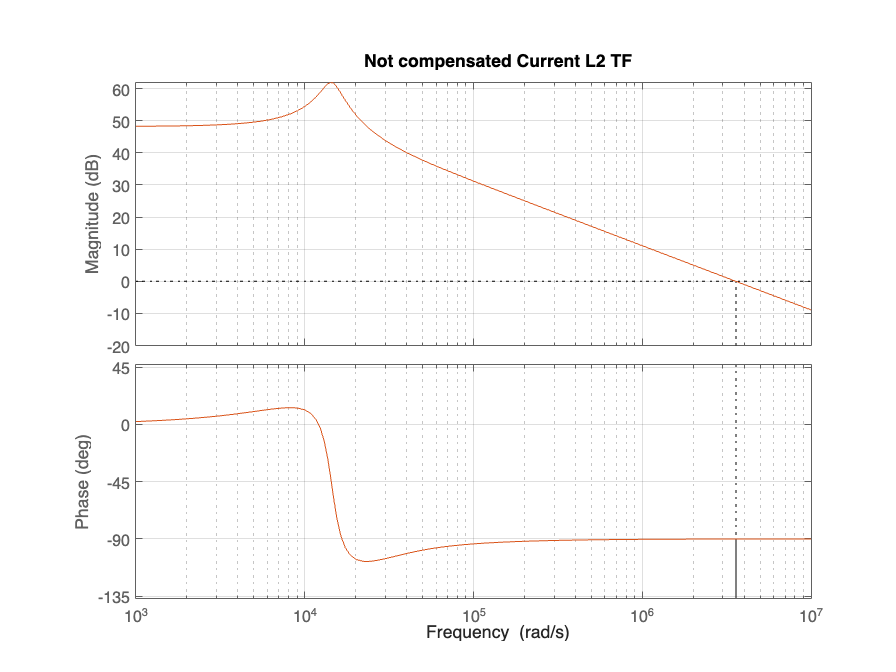


% Função de transferência de malha aberta não compensada
% usando ss
FTLA_NC_iL_s = FT_G_iLd * Ki * KPWM;

Gi_dc = Vin/(Dp^2*Rload);
FTLA_NC_iL2 = FT_G_iL2d * Ki * KPWM;

% Calcular magnitude e fase na frequência de cruzamento
figure;
bode(FTLA_NC_iL2);
hold on;
margin(FTLA_NC_iL2);
title('Not compensated Current L2 TF')
grid on;


[mag_i, phase_i, ~] = bode(FTLA_NC_iL2, wci);
grid on;

mag_i_abs = mag_i(1);
phase_i_deg = phase_i(1);
phase_i_rad = phase_i_deg * pi/180;
fprintf('At ωc = %.2f rad/s (%.2f Hz):\n', wci, wci/(2*pi));

At ωc = 12566.37 rad/s (2000.00 Hz):


fprintf('  |FTLA_NC| = %.2f dB (%.4e linear)\n', 20*log10(mag_i_abs), mag_i_abs);

  |FTLA_NC| = 59.33 dB (9.2573e+02 linear)


fprintf('  arg or ∠FTLA_NC = %.2f° (%.4f rad)\n', phase_i_deg, phase_i_rad);

  arg or ∠FTLA_NC = -5.72° (-0.0998 rad)



% Cálculo do zero do controlador (ωz)
tan_arg_i = tan(MF_i - pi/2 - phase_i_rad);
if tan_arg_i > 0
    wz_i = wci / tan_arg_i;
else
    wz_i = wci / 10;
    fprintf('  tan_arg = %.4f, usando wz_i = %.2f rad/s\n', tan_arg_i, wz_i);
end

  tan_arg = -0.4511, usando wz_i = 1256.64 rad/s


if wz_i <= 0
    wz_i = wci / 10;
    fprintf('  Ajuste: wz_i = %.2f rad/s\n', wz_i);
end
% Cálculo do ganho do controlador (kc)
kc_i = wci / (sqrt(wci^2 + wz_i^2) * mag_i_abs);
fprintf('\nPARÂMETROS DO CONTROLADOR PI (CORRENTE L2):\n');


PARÂMETROS DO CONTROLADOR PI (CORRENTE L2):


fprintf('  ωz l2 = %.2f rad/s (fz = %.2f Hz)\n', wz_i, wz_i/(2*pi));

  ωz l2 = 1256.64 rad/s (fz = 200.00 Hz)


fprintf('  τz l2 = 1/ωz = %.4f s\n', 1/wz_i);

  τz l2 = 1/ωz = 0.0008 s


fprintf('  kc l2 = %.4e\n', kc_i);

  kc l2 = 1.0749e-03



% Controlador PI para a corrente
Ci = tf(kc_i * [1, wz_i], [1, 0]);
FTLA_C_il2 = FTLA_NC_iL2 * Ci;
fprintf(' Controller');

 Controller

fprintf('  C_i(s) = %.4e * (s + %.2f) / s\n', kc_i, wz_i);

  C_i(s) = 1.0749e-03 * (s + 1256.64) / s


fprintf('  C_i(s) = %.4e + %.4e / s\n', kc_i, kc_i * wz_i);

  C_i(s) = 1.0749e-03 + 1.3507e+00 / s


[Gm_i, Pm_i, Wcg_i, Wcp_i] = margin(FTLA_C_il2);
fprintf('  Margem de ganho:  %.2f dB\n', 20*log10(Gm_i));

  Margem de ganho:  Inf dB


fprintf('  Margem de fase:   %.2f°\n', Pm_i);

  Margem de fase:   92.39°


fprintf('  Frequência de cruzamento de ganho: %.2f rad/s (%.2f Hz)\n', Wcp_i, Wcp_i/(2*pi));

  Frequência de cruzamento de ganho: 16023.14 rad/s (2550.16 Hz)


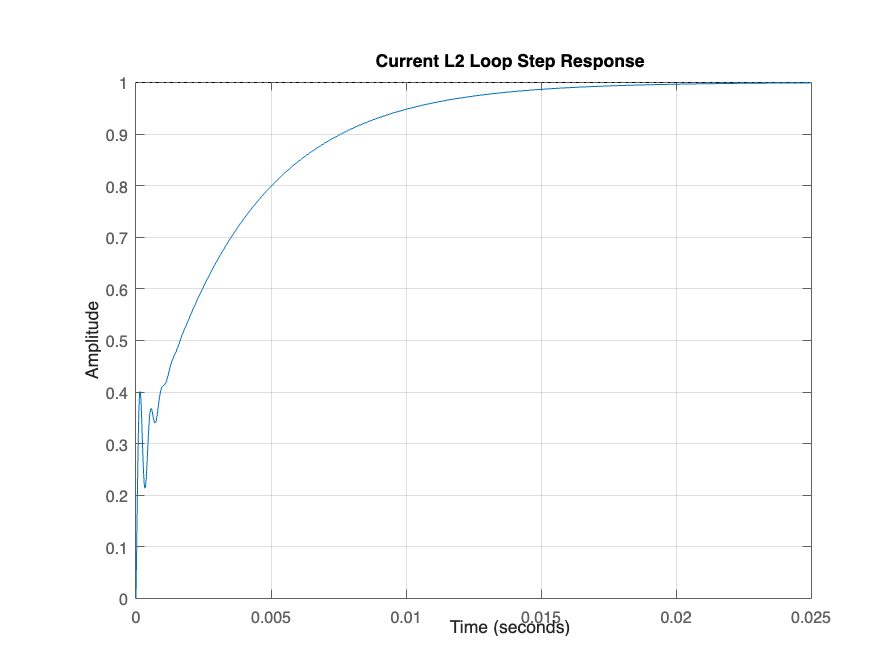



%% Closed-loop current
CL_i = feedback(FTLA_C_il2, 1);
figure; 
step(CL_i); 
grid on; 
title('Current L2 Loop Step Response');

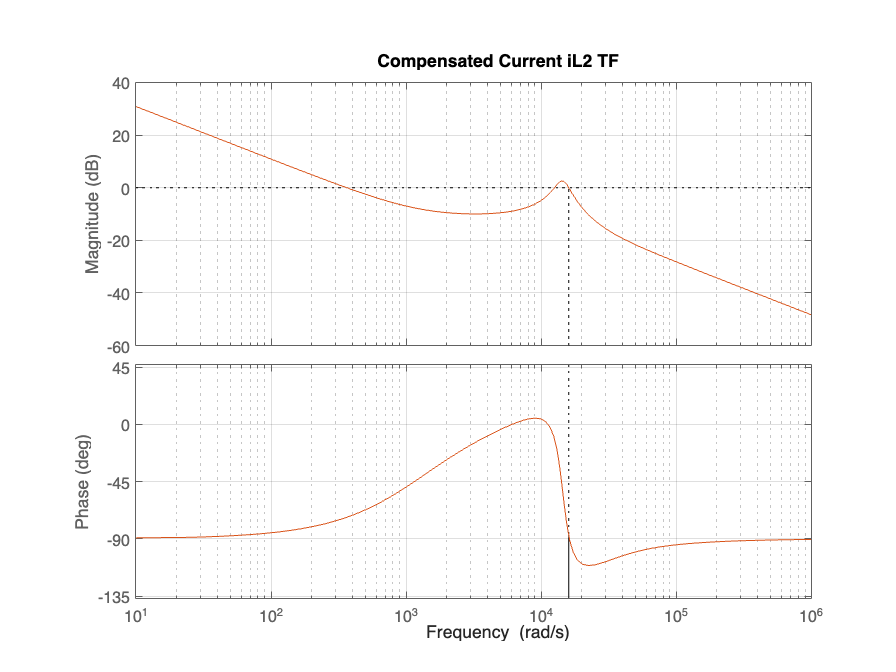



% Função de transferência de malha aberta compensada
FTLA_ci = FTLA_NC_iL2 * Ci;
figure;
bode(FTLA_C_il2);
hold on;
margin(FTLA_C_il2);
title('Compensated Current iL2 TF')
grid on;


% Função de transferência de malha fechada (desacoplamento)
%FTMF_i = Ci * KPWM * FT_G_iLd / (1 + Ki * Ci * KPWM * FT_G_iLd);
FTMF_i = Ci * KPWM * FT_G_iL2d / (1 + Ki * Ci * KPWM * FT_G_iL2d);
tau_ci2 = 1/wz_i;


% Uncompensated loop gain

fprintf('\nPARÂMETROS DO CONTROLADOR PI (CORRENTE L1):\n');


PARÂMETROS DO CONTROLADOR PI (CORRENTE L1):



FTLA_nci = GiL1d * Ki * Kpwm;
FTLA_nci_simp = Gi_dc * Ki * Kpwm;
[mag_nci, ph_nci] = bode(FTLA_nci, wci);
mag_nci = mag_nci(1); ph_nci = ph_nci(1)*pi/180;
w_zi = wci / tan(PM - pi/2 - ph_nci);
K_ci = wci / (mag_nci * sqrt(wci^2 + w_zi^2));
%C_i = K_ci * (s + w_zi) / s;
C_i = tf(K_ci * [1, w_zi], [1, 0]);

fprintf('  ωz il1 = %.2f rad/s (fz = %.2f Hz)\n', w_zi, w_zi/(2*pi));

  ωz il1 = -27856.60 rad/s (fz = -4433.52 Hz)


fprintf('  τz il1 = 1/ωz = %.4f s\n', 1/w_zi);

  τz il1 = 1/ωz = -0.0000 s


fprintf('  kc il1 = %.4e\n', K_ci);

  kc il1 = 4.4419e-04



fprintf('  C_i(s) = %.4e * (s + %.2f) / s\n', K_ci, w_zi);

  C_i(s) = 4.4419e-04 * (s + -27856.60) / s


fprintf('  C_i(s) = %.4e + %.4e / s\n', K_ci, K_ci * w_zi);

  C_i(s) = 4.4419e-04 + -1.2374e+01 / s


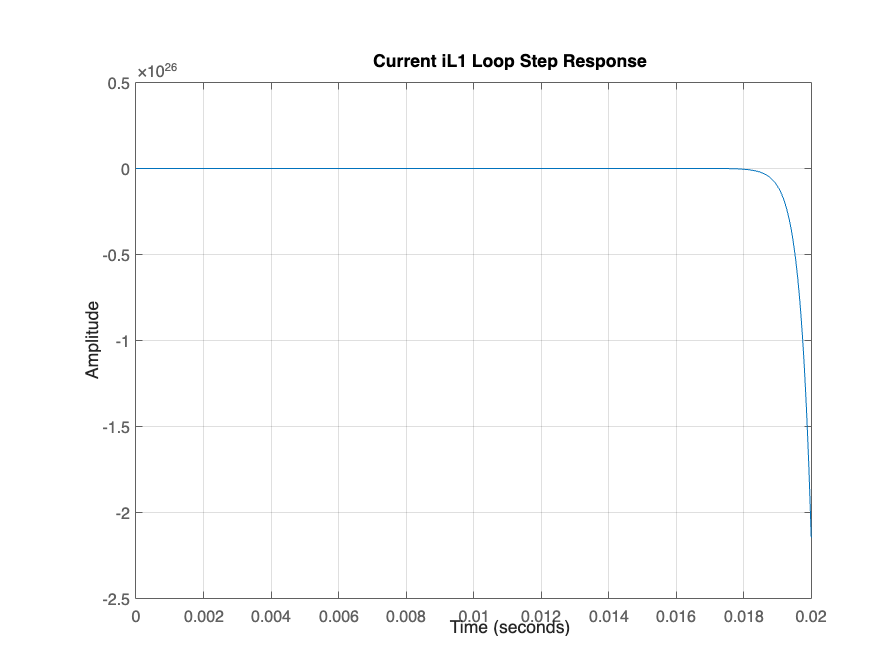

FTLA_ci = FTLA_nci * C_i;

%% Closed-loop current
CLi = feedback(FTLA_ci, 1);
figure; 
step(CLi); 
grid on; 
title('Current iL1 Loop Step Response');

FTMF_i1 = C_i * KPWM * FT_G_iLd / (1 + Ki * C_i * KPWM * FT_G_iLd);



%% ========================================================================

###  PROJETO DO CONTROLADOR PI PARA A MALHA DE TENSÃO (Gvi)

fprintf(' PROJETO DO CONTROLADOR PI - MALHA DE TENSÃO (vo)\n');

 PROJETO DO CONTROLADOR PI - MALHA DE TENSÃO (vo)


 
% Especificações da malha de tensão - planta lenta fase maior
wc_v = 500 * 2 * pi;                % Frequência de cruzamento (rad/s) - 250 hz
MF_v = 80 * pi/180;         % Margem de fase desejada (90° em radianos)

% Função de transferência de malha aberta não compensada
FTLA_NC_v = FT_G_Vi * Kv * FTMF_i; 
FTLA_NC_v_ss = Gvi * Kv * FTMF_i; 

% Calcular magnitude e fase na frequência de cruzamento
[mag_v, phase_v, ~] = bode(FTLA_NC_v, wc_v);
mag_v_abs = mag_v(1);
phase_v_deg = phase_v(1);
phase_v_rad = phase_v_deg * pi/180;
fprintf('Em ωc = %.2f rad/s (%.2f Hz):\n', wc_v, wc_v/(2*pi));

Em ωc = 3141.59 rad/s (500.00 Hz):


fprintf('  |FTLA_NC| = %.2f dB (%.4e linear)\n', 20*log10(mag_v_abs), mag_v_abs);

  |FTLA_NC| = -38.10 dB (1.2443e-02 linear)


fprintf('  ∠FTLA_NC = %.2f° (%.4f rad)\n', phase_v_deg, phase_v_rad);

  ∠FTLA_NC = 326.62° (5.7006 rad)


% Cálculo do zero do controlador (ωz)
tan_arg_v = tan(MF_v - pi/2 - phase_v_rad);
wz_v = wc_v /tan_arg_v;
tau_v = 1 / wz_v

tau_v = 1.3762e-04


%%% Calcular magnitude e fase na frequência de cruzamento
[mag_v, phase_v, ~] = bode(FTLA_NC_v_ss, wc_v);
smag_v_abs = mag_v(1);
sphase_v_deg = phase_v(1);
sphase_v_rad = phase_v_deg * pi/180;
fprintf('Em ωc = %.2f rad/s (%.2f Hz):\n', wc_v, wc_v/(2*pi));

Em ωc = 3141.59 rad/s (500.00 Hz):


fprintf('  |FTLA_NC| = %.2f dB (%.4e linear)\n', 20*log10(smag_v_abs), smag_v_abs);

  |FTLA_NC| = -28.24 dB (3.8710e-02 linear)


fprintf('  ∠FTLA_NC = %.2f° (%.4f rad)\n', sphase_v_deg, sphase_v_rad);

  ∠FTLA_NC = -13.29° (5.7006 rad)




% Cálculo do zero do controlador (ωz)
stan_arg_v = tan(MF_v - pi/2 - phase_v_rad);
wz_vs = wc_v / stan_arg_v;
tau_vs = 1 / wz_vs

tau_vs = 1.3762e-04


% Cálculo do ganho do controlador (kc)
kc_v = wc_v / (sqrt(wc_v^2 + wz_v^2) * mag_v_abs);
kc_vs = wc_v / (sqrt(wc_v^2 + wz_vs^2) * smag_v_abs);

fprintf('\nPARÂMETROS DO CONTROLADOR PI (TENSÃO):\n');


PARÂMETROS DO CONTROLADOR PI (TENSÃO):


fprintf('  ωzv = %.2f rad/s (fz = %.2f Hz)\n', wz_v, wz_v/(2*pi));

  ωzv = 7266.19 rad/s (fz = 1156.45 Hz)


fprintf('  τzv = 1/ωz = %.4f s\n', 1/wz_v);

  τzv = 1/ωz = 0.0001 s


fprintf('  kcv = %.4e\n', kc_v);

  kcv = 3.1893e+01



fprintf('\nPARÂMETROS DO CONTROLADOR PI ss (TENSÃO):\n');


PARÂMETROS DO CONTROLADOR PI ss (TENSÃO):


fprintf('  ωz = %.2f rad/s (fz = %.2f Hz)\n', wz_vs, wz_vs/(2*pi));

  ωz = 7266.19 rad/s (fz = 1156.45 Hz)


fprintf('  τz = 1/ωz = %.4f s\n', tau_vs);

  τz = 1/ωz = 0.0001 s


fprintf('  kc = %.4e\n', kc_vs);

  kc = 1.0252e+01



% Controlador PI para a tensão
Cv = tf(kc_v * [1, wz_v], [1, 0]);
Cv_s = tf(kc_vs * [1, wz_vs], [1, 0]);

fprintf('  C_v(s) = %.4e * (s + %.2f) / s\n', kc_v, wz_v);

  C_v(s) = 3.1893e+01 * (s + 7266.19) / s


fprintf('  C_v(s) = %.4e + %.4e / s\n', kc_v, kc_v * wz_v);

  C_v(s) = 3.1893e+01 + 2.3174e+05 / s



fprintf('  C_vs(s) = %.4e * (s + %.2f) / s\n', kc_vs, wz_vs);

  C_vs(s) = 1.0252e+01 * (s + 7266.19) / s


fprintf('  C_vs(s) = %.4e + %.4e / s\n', kc_vs, kc_vs * wz_vs);

  C_vs(s) = 1.0252e+01 + 7.4493e+04 / s


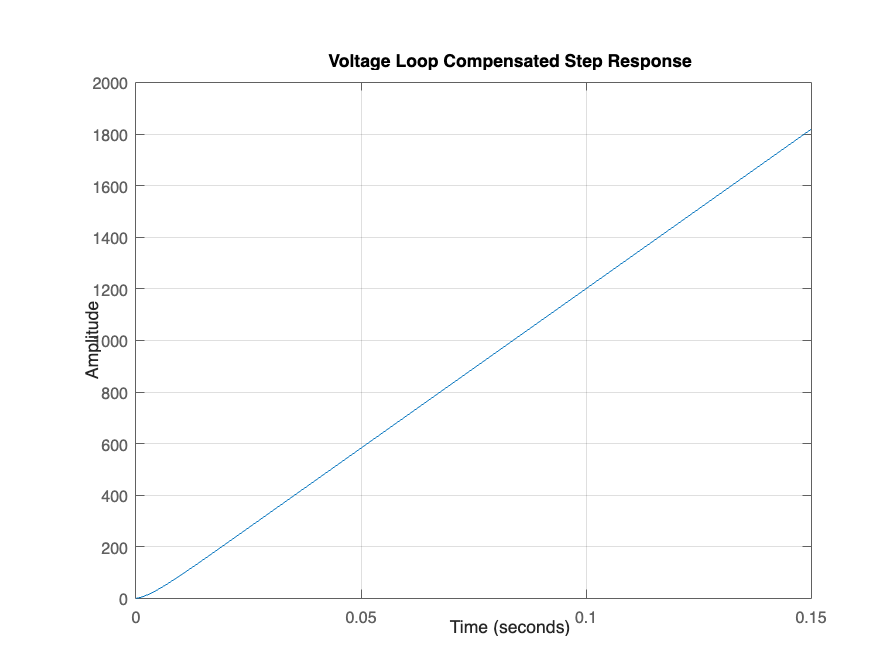


% Função de transferência de malha aberta compensada
FTLA_C_v = FTLA_NC_v * Cv;
figure; 
step(FTLA_C_v); 
grid on; title('Voltage Lofop Compensated Step Response');

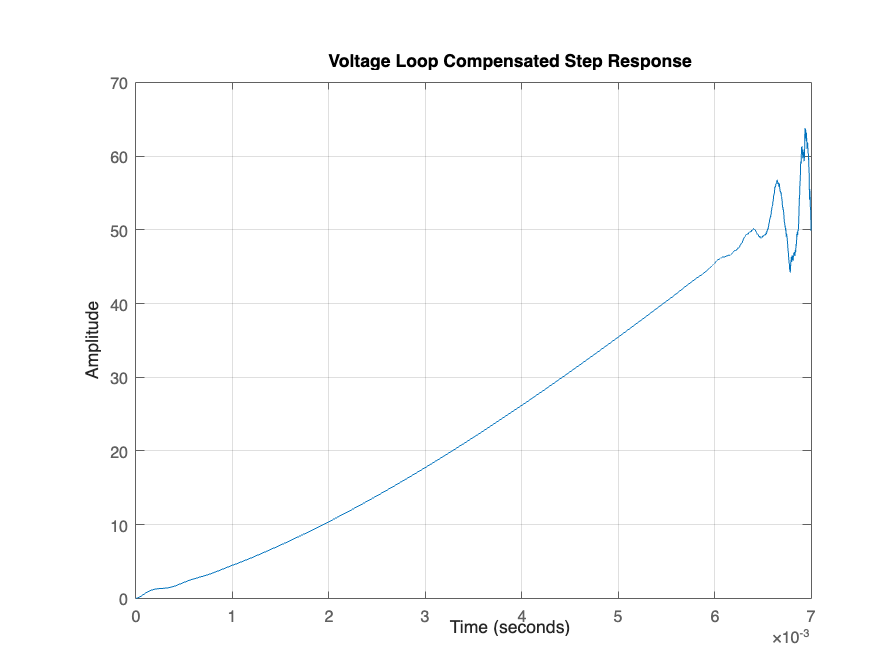


FTLA_C_vs = FTLA_NC_v_ss * Cv_s;
figure; 
step(FTLA_C_vs); 
grid on; title('Voltage Loop Compensated Step Response');

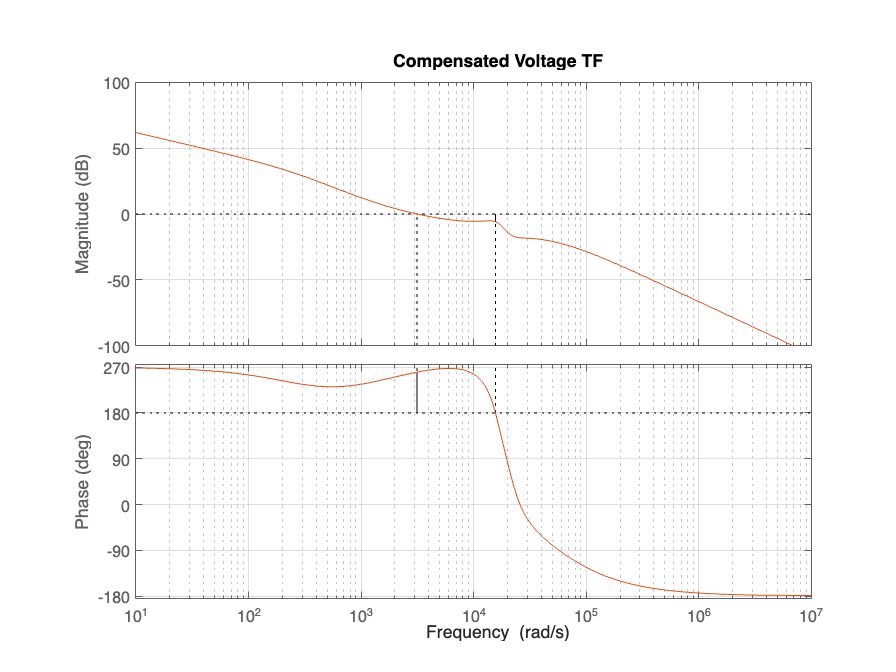


% Margens de estabilidade
figure;
bode(FTLA_C_v);
hold on;
margin(FTLA_C_v);
title('Compensated Voltage TF')
grid on;

### Comparativo

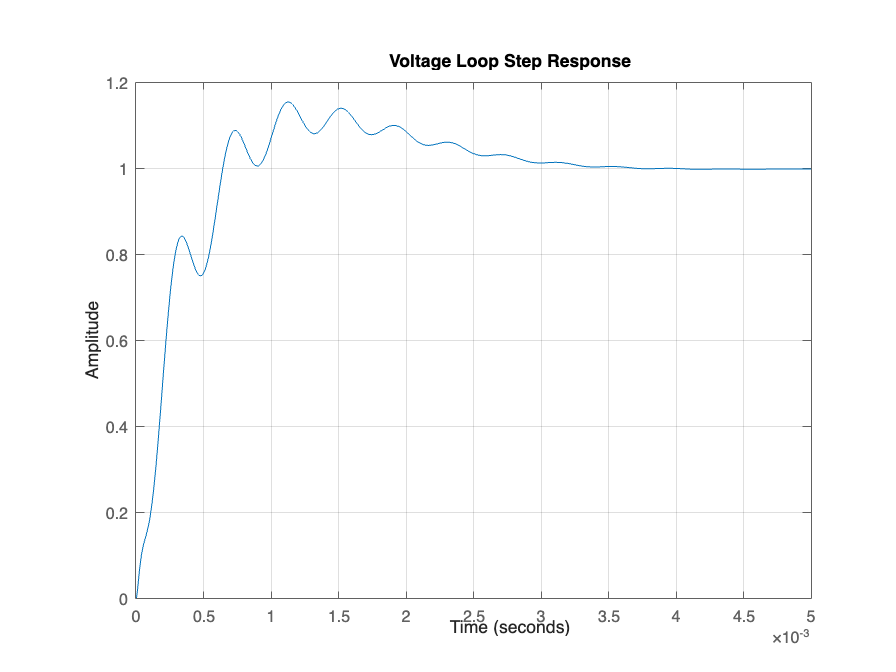


%% Closed-loop voltage
CL_i = feedback(FTLA_C_v, 1);
figure; 
step(CL_i); 
grid on; title('Voltage Loop Step Response');

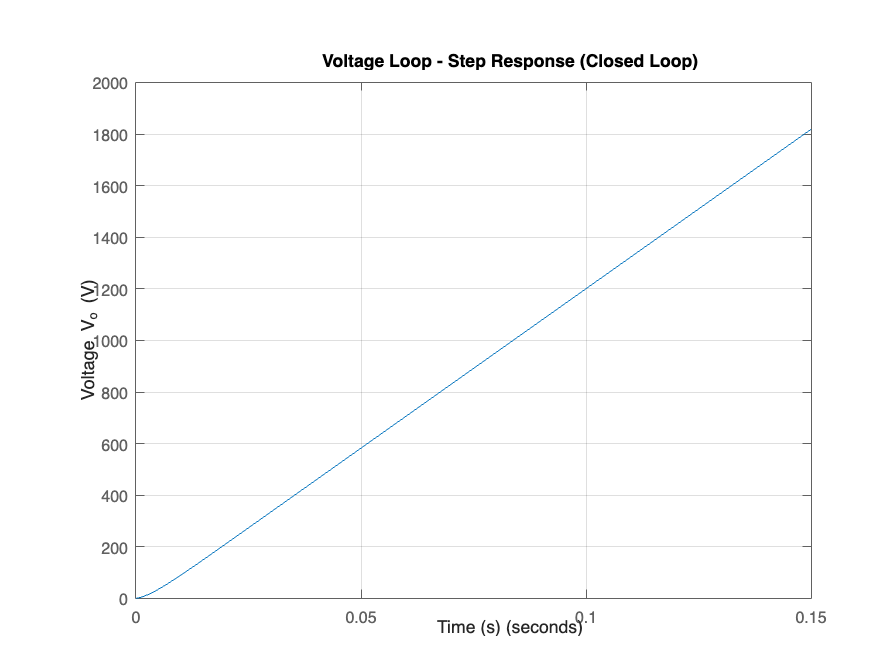


% Resposta ao degrau da malha fechada (tensão)
figure;
step(FTLA_C_v);
grid on;
title('Voltage Loop - Step Response (Closed Loop)');
xlabel('Time (s)');
ylabel('Voltage V_o (V)');

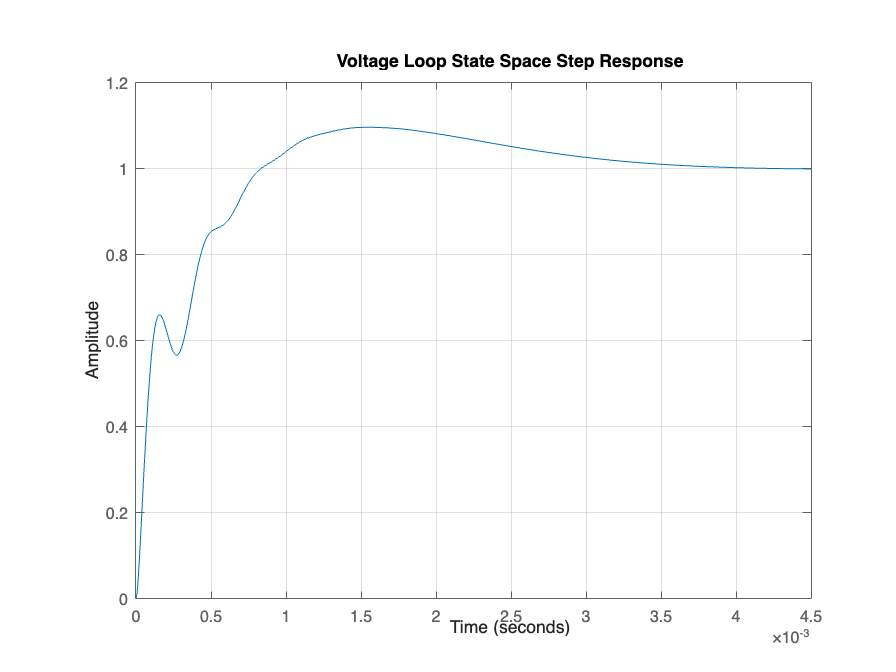



%% Closed-loop voltage
CL_is = feedback(FTLA_C_vs, 1);
figure; 
step(CL_is); 
grid on; title('Voltage Loop State Space Step Response');



% Margens de estabilidade
[Gm_v, Pm_v, Wcg_v, Wcp_v] = margin(FTLA_C_v);

fprintf('\nMARGENS DE ESTABILIDADE (MALHA DE TENSÃO):\n');


MARGENS DE ESTABILIDADE (MALHA DE TENSÃO):


fprintf('  Margem de ganho:  %.2f dB\n', 20*log10(Gm_v));

  Margem de ganho:  5.79 dB


fprintf('  Margem de fase:   %.2f°\n', Pm_v);

  Margem de fase:   80.00°


fprintf('  Frequência de cruzamento de ganho: %.2f rad/s (%.2f Hz)\n', Wcp_v, Wcp_v/(2*pi));

  Frequência de cruzamento de ganho: 3141.60 rad/s (500.00 Hz)




% Margens de estabilidade
[Gm_vs, Pm_vs, Wcg_vs, Wcp_vs] = margin(FTLA_C_vs);

fprintf('\nMARGENS DE ESTABILIDADE (MALHA DE TENSÃO):\n');


MARGENS DE ESTABILIDADE (MALHA DE TENSÃO):


fprintf('  Margem de ganho:  %.2f dB\n', 20*log10(Gm_vs));

  Margem de ganho:  Inf dB


fprintf('  Margem de fase:   %.2f°\n', Pm_vs);

  Margem de fase:   76.26°


fprintf('  Frequência de cruzamento de ganho: %.2f rad/s (%.2f Hz)\n', Wcp_vs, Wcp_vs/(2*pi));

  Frequência de cruzamento de ganho: 18213.69 rad/s (2898.80 Hz)


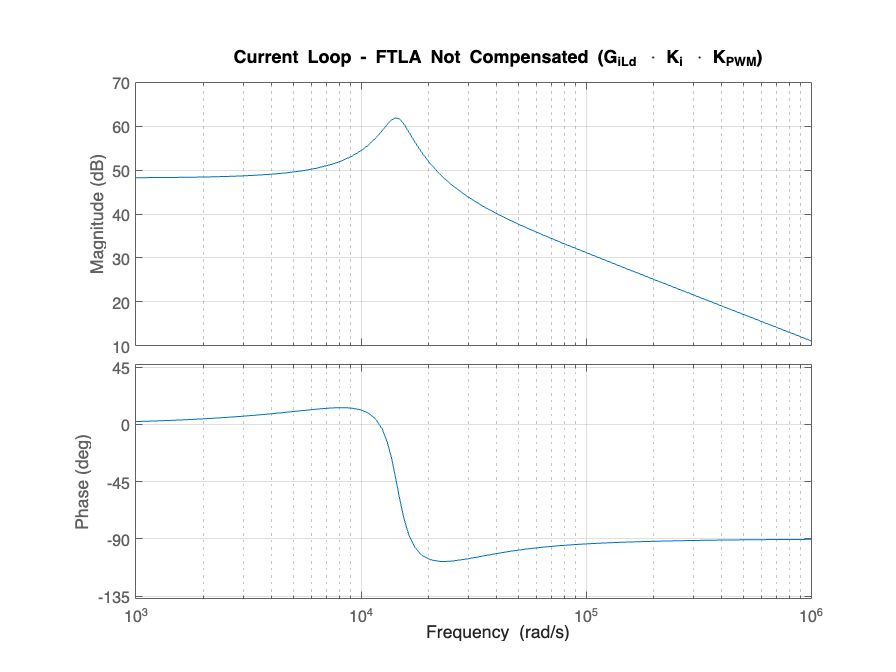



%  Bode da FTLA não compensada (corrente)
figure;
bode(FTLA_NC_iL2);
grid on;
title('Current Loop - FTLA Not Compensated (G_{iLd} \cdot K_i \cdot K_{PWM})');

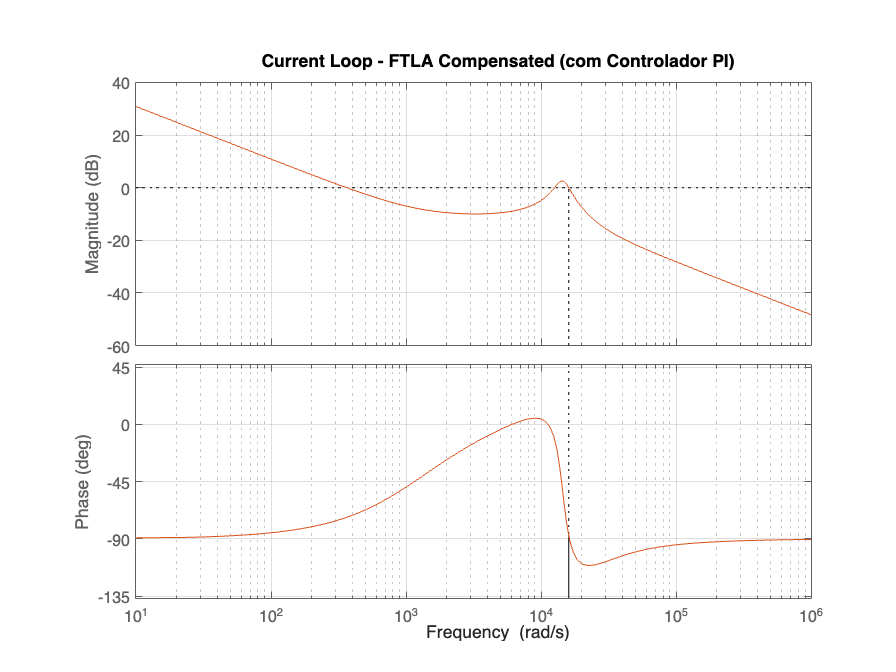


% Bode da FTLA compensada (corrente)
figure;
bode(FTLA_C_il2);
hold on;
margin(FTLA_C_il2);
grid on;
title('Current Loop - FTLA Compensated (com Controlador PI)');

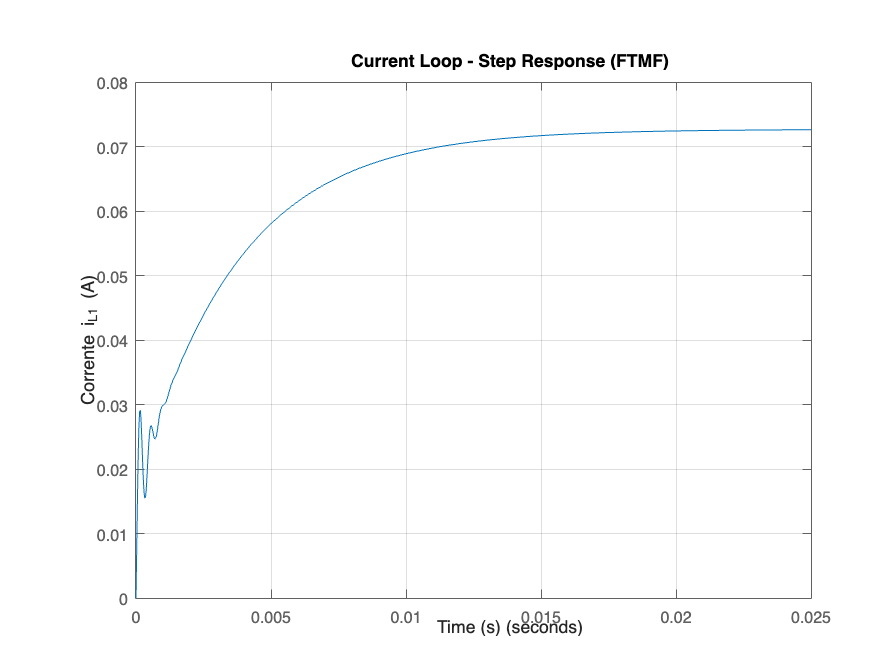


%  Resposta ao degrau da malha fechada (corrente)
figure;
step(FTMF_i);
grid on;
title('Current Loop - Step Response (FTMF)');
xlabel('Time (s)');
ylabel('Corrente i_{L1} (A)');

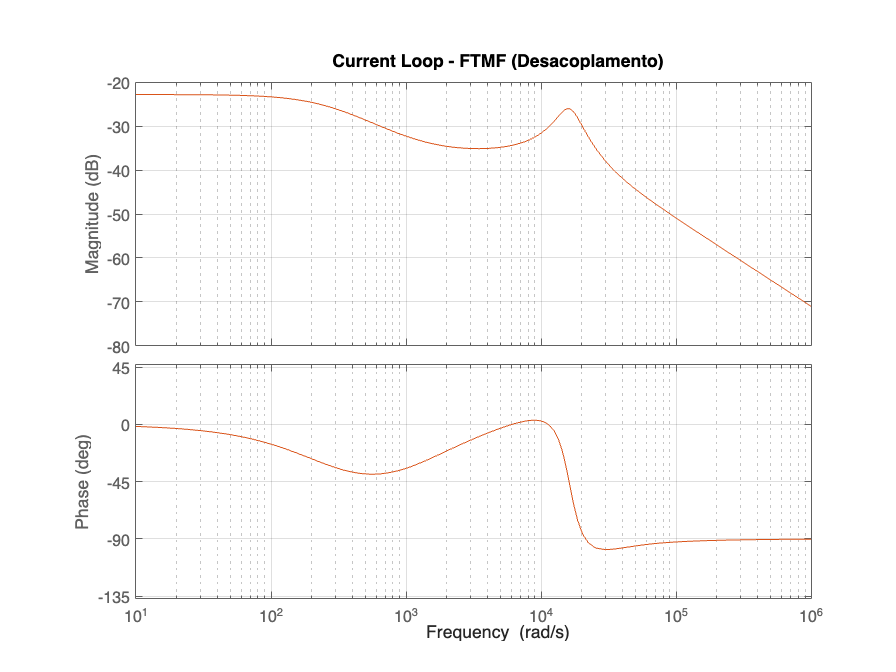


% Bode da FTMF (corrente)
figure;
bode(FTMF_i);
hold on;
margin(FTMF_i);
grid on;
title('Current Loop - FTMF (Desacoplamento)');

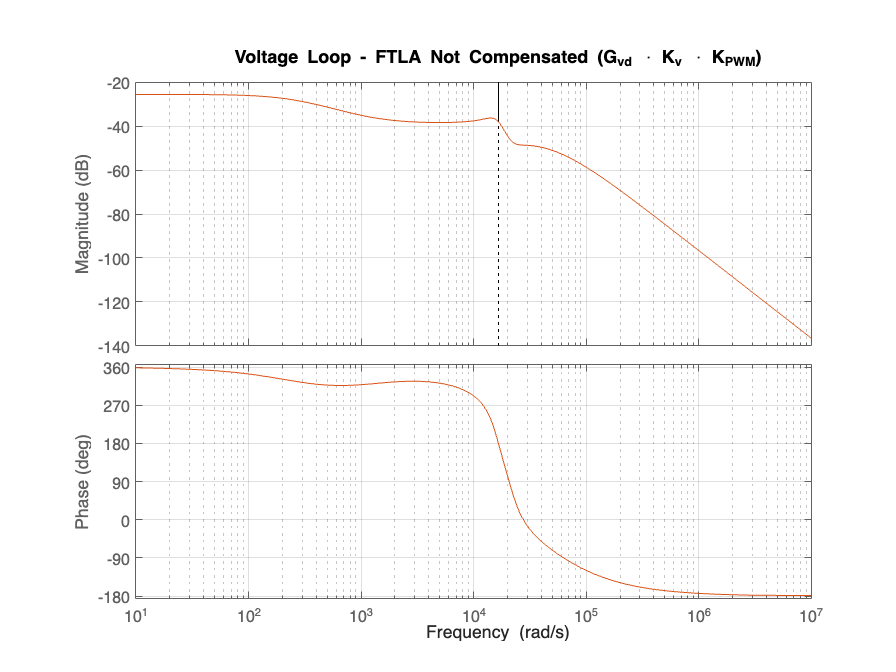


%%  GRÁFICOS - MALHA DE TENSÃO

% Bode da FTLA não compensada (tensão)
figure;
bode(FTLA_NC_v);
hold on;
margin(FTLA_NC_v);
grid on;
title('Voltage Loop - FTLA Not Compensated (G_{vd} \cdot K_v \cdot K_{PWM})');

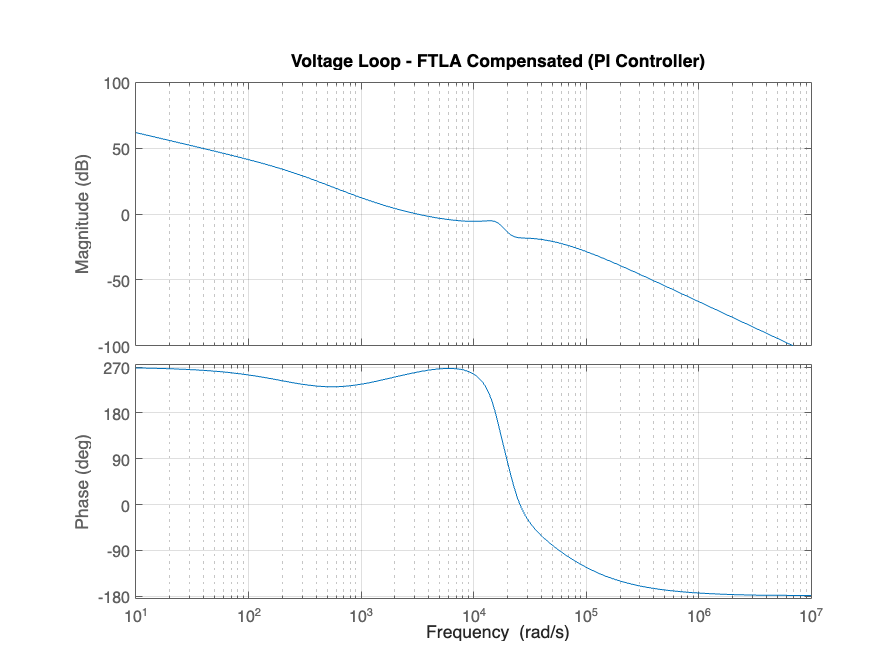


%  Bode da FTLA compensada (tensão)
figure;
bode(FTLA_C_v);
grid on;
title('Voltage Loop - FTLA Compensated (PI Controller)');

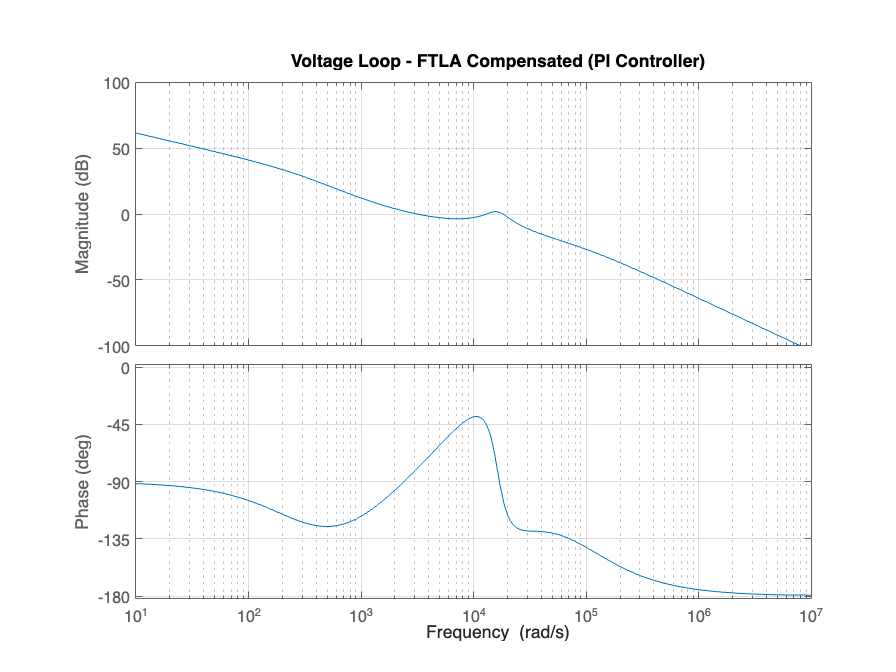



%  Bode da FTLA compensada (tensão)
figure;
bode(FTLA_C_vs);
grid on;
title('Voltage Loop - FTLA Compensated (PI Controller)');

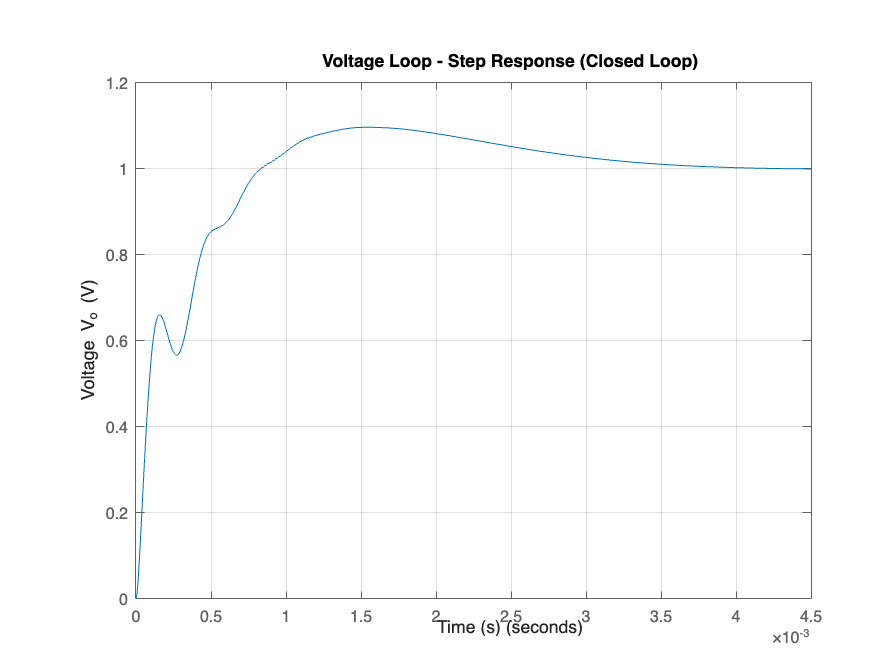


% Resposta ao degrau da malha fechada (tensão)
FTMF_v = feedback(FTLA_C_vs, 1);
figure;
step(FTMF_v);
grid on;
title('Voltage Loop - Step Response (Closed Loop)');
xlabel('Time (s)');
ylabel('Voltage V_o (V)');

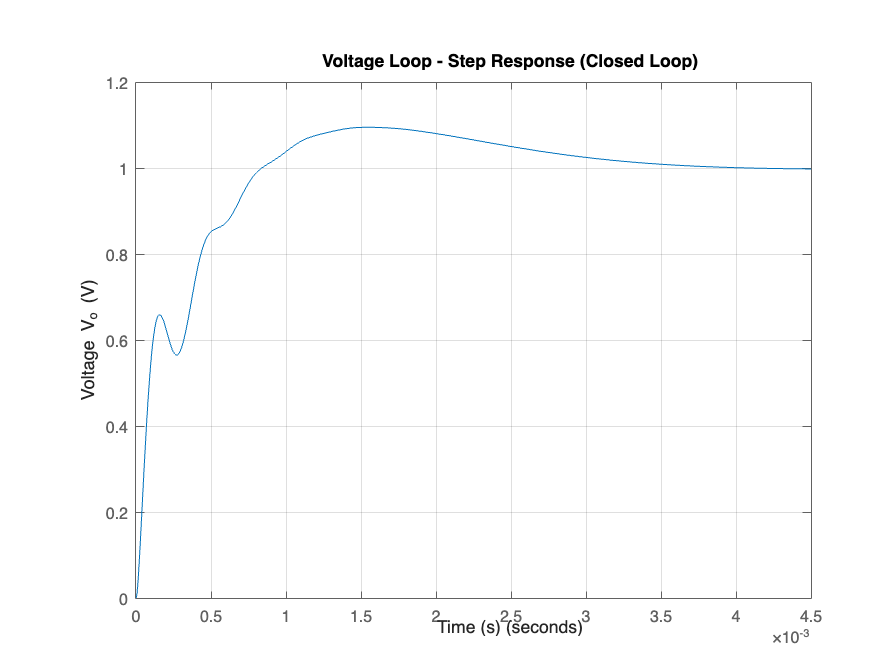



% Resposta ao degrau da malha fechada (tensão)
FTMF_v = feedback(FTLA_C_vs, 1);
figure;
step(FTMF_v);
grid on;
title('Voltage Loop - Step Response (Closed Loop)');
xlabel('Time (s)');
ylabel('Voltage V_o (V)');

% print(gcf, 'figures/stepclosedloop.png',  '-depsc', '-r300');

save('modelo_cuk_completo.mat', 'FT_G_iLd', 'FT_G_iL2d', 'A', 'F', 'Ci', 'Cv', ...
     'FTLA_C_il2', 'FTLA_C_v', 'FTMF_i');

fprintf('Controlador de Corrente (iL1):\n');

Controlador de Corrente (iL1):


fprintf('  C_i(s) = %.4e * (s + %.2f) / s\n', kc_i, wz_i);

  C_i(s) = 1.0749e-03 * (s + 1256.64) / s


fprintf('  C_i(s) = %.4e + %.4e / s\n', kc_i, kc_i * wz_i);

  C_i(s) = 1.0749e-03 + 1.3507e+00 / s


fprintf('  ωc = %.2f rad/s (%.2f Hz)\n', wci, wci/(2*pi));

  ωc = 12566.37 rad/s (2000.00 Hz)


fprintf('  MF  = %.2f°\n', Pm_i);

  MF  = 92.39°


fprintf('\nControlador de Voltage (vo):\n');


Controlador de Voltage (vo):


fprintf('  C_v(s) = %.4e * (s + %.2f) / s\n', kc_v, wz_v);

  C_v(s) = 3.1893e+01 * (s + 7266.19) / s


fprintf('  C_v(s) = %.4e + %.4e / s\n', kc_v, kc_v * wz_v);

  C_v(s) = 3.1893e+01 + 2.3174e+05 / s


fprintf('  ωc = %.2f rad/s (%.2f Hz)\n', wc_v, wc_v/(2*pi));

  ωc = 3141.59 rad/s (500.00 Hz)


fprintf('  MF  = %.2f°\n', Pm_v);

  MF  = 80.00°
